# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 07-Aug-2021 11:21:55

## Load the Pretrained Parameters

params = load("C:\Users\12424\Desktop\Acadimic\Computer Science\Master 1\Research Methodology Computer Science\Project\params_2021_08_07__11_21_16.mat");

## **Import Data**

Imort the art dataset to train and validate for claasification their artists.

art_image_dataset = imageDatastore("C:\Users\12424\Desktop\Acadimic\Computer Science\Master 1\Research Methodology Computer Science\Project\Dataset\wikiart","IncludeSubfolders",true,"LabelSource","foldernames");
[art_image_Train, art_image_Validate] = splitEachLabel(art_image_dataset, 0.7, 'randomized');

Resize the image from dataset to a better match format for googleNet model.

resized_art_Train = augmentedImageDatastore([224 224 3], art_image_Train,"ColorPreprocessing","gray2rgb");
resized_art_Validate = augmentedImageDatastore([224 224 3],art_image_Validate,"ColorPreprocessing","gray2rgb");

## Set Training Options

Define the options for training the dataset.

options = trainingOptions("sgdm", ...
    "ExecutionEnvironment","gpu", ...
    "InitialLearnRate", 0.001, ...
    "LearnRateDropPeriod", 5, ...
    "MaxEpochs", 10, ...
    "MiniBatchSize", 12, ...
    "Momentum", 0.1, ...
    "Shuffle", "every-epoch", ...
    "ValidationFrequency", 4000, ...
    "Plots","training-progress", ...
    "ValidationData", resized_art_Validate)

options =   TrainingOptionsSGDM with properties:

                    Momentum: 0.1000
            InitialLearnRate: 1.0000e-03
           LearnRateSchedule: 'none'
         LearnRateDropFactor: 0.1000
         LearnRateDropPeriod: 5
            L2Regularization: 1.0000e-04
     GradientThresholdMethod: 'l2norm'
           GradientThreshold: Inf
                   MaxEpochs: 10
               MiniBatchSize: 12
                     Verbose: 1
            VerboseFrequency: 50
              ValidationData: [1×1 augmentedImageDatastore]
         ValidationFrequency: 4000
          ValidationPatience: Inf
                     Shuffle: 'every-epoch'
              CheckpointPath: ''
        ExecutionEnvironment: 'gpu'
                  WorkerLoad: []
                   OutputFcn: []
                       Plots: 'training-progress'
              SequenceLength: 'longest'
        SequencePaddingValue: 0
    Se

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([224 224 3],"Name","data")
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2])
    reluLayer("Name","conv1-relu_7x7")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","conv2-relu_3x3_reduce")
    convolution2dLayer([3 3],192,"Name","conv2-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","conv2-relu_3x3")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_5x5_reduce")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_3x3_reduce")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_3x3_reduce")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_5x5_reduce")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_5x5_reduce")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_3x3_reduce")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_3x3_reduce")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4c-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_3x3_reduce")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4c-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_3x3_reduce")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4d-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4d-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4e-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_3x3_reduce")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4e-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_3x3_reduce")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_3x3_reduce")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1")
    dropoutLayer(0.4,"Name","pool5-drop_7x7_s1")
    fullyConnectedLayer(27,"Name","fc","BiasLearnRateFactor",2)
    softmaxLayer("Name","prob")
    classificationLayer("Name","output")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-pool");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-1x1");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-5x5_reduce");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj","inception_3a-output/in4");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1","inception_3a-output/in1");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3","inception_3a-output/in2");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5","inception_3a-output/in3");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-1x1");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-pool");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1","inception_3b-output/in1");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5","inception_3b-output/in3");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3","inception_3b-output/in2");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj","inception_3b-output/in4");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-5x5_reduce");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-pool");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-1x1");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj","inception_4a-output/in4");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1","inception_4a-output/in1");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3","inception_4a-output/in2");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5","inception_4a-output/in3");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-pool");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-1x1");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1","inception_4b-output/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5","inception_4b-output/in3");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj","inception_4b-output/in4");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3","inception_4b-output/in2");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-pool");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-1x1");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj","inception_4c-output/in4");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1","inception_4c-output/in1");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5","inception_4c-output/in3");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3","inception_4c-output/in2");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-1x1");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-pool");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj","inception_4d-output/in4");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1","inception_4d-output/in1");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3","inception_4d-output/in2");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5","inception_4d-output/in3");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-pool");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-1x1");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1","inception_4e-output/in1");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj","inception_4e-output/in4");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3","inception_4e-output/in2");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5","inception_4e-output/in3");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-5x5_reduce");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-1x1");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-pool");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1","inception_5a-output/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj","inception_5a-output/in4");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5","inception_5a-output/in3");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3","inception_5a-output/in2");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-1x1");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-pool");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5","inception_5b-output/in3");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3","inception_5b-output/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1","inception_5b-output/in1");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj","inception_5b-output/in4");

## Plot Layers

Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:05:01 |        8.33% |        1.74% |       3.3670 |       3.6132 |          0.0010 |


|       1 |          50 |       00:05:16 |       25.00% |              |       2.9198 |              |          0.0010 |


|       1 |         100 |       00:05:31 |       16.67% |              |       3.1432 |              |          0.0010 |


|       1 |         150 |       00:05:46 |       16.67% |              |       3.1113 |              |          0.0010 |


|       1 |         200 |       00:06:01 |       16.67% |              |       2.8023 |              |          0.0010 |


|       1 |         250 |       00:06:16 |        8.33% |              |       2.9627 |              |          0.0010 |


|       1 |         300 |       00:06:31 |       25.00% |              |       2.6792 |              |          0.0010 |


|       1 |         350 |       00:06:46 |       33.33% |              |       2.3344 |              |          0.0010 |


|       1 |         400 |       00:07:01 |        8.33% |              |       2.8172 |              |          0.0010 |


|       1 |         450 |       00:07:17 |       16.67% |              |       2.9398 |              |          0.0010 |


|       1 |         500 |       00:07:33 |        0.00% |              |       3.0653 |              |          0.0010 |


|       1 |         550 |       00:07:48 |        8.33% |              |       2.7972 |              |          0.0010 |


|       1 |         600 |       00:08:02 |       16.67% |              |       2.6303 |              |          0.0010 |


|       1 |         650 |       00:08:18 |        8.33% |              |       3.4489 |              |          0.0010 |


|       1 |         700 |       00:08:33 |       25.00% |              |       2.8012 |              |          0.0010 |


|       1 |         750 |       00:08:48 |       16.67% |              |       2.6661 |              |          0.0010 |


|       1 |         800 |       00:09:03 |        8.33% |              |       3.1721 |              |          0.0010 |


|       1 |         850 |       00:09:18 |       25.00% |              |       2.9525 |              |          0.0010 |


|       1 |         900 |       00:09:33 |       41.67% |              |       2.7586 |              |          0.0010 |


|       1 |         950 |       00:09:48 |       16.67% |              |       2.9074 |              |          0.0010 |


|       1 |        1000 |       00:10:03 |       16.67% |              |       2.5821 |              |          0.0010 |


|       1 |        1050 |       00:10:19 |        8.33% |              |       3.0180 |              |          0.0010 |


|       1 |        1100 |       00:10:35 |        8.33% |              |       2.8665 |              |          0.0010 |


|       1 |        1150 |       00:10:50 |       25.00% |              |       2.6117 |              |          0.0010 |


|       1 |        1200 |       00:11:05 |        8.33% |              |       2.6201 |              |          0.0010 |


|       1 |        1250 |       00:11:20 |       16.67% |              |       2.4807 |              |          0.0010 |


|       1 |        1300 |       00:11:35 |       25.00% |              |       2.6658 |              |          0.0010 |


|       1 |        1350 |       00:11:51 |       16.67% |              |       2.7479 |              |          0.0010 |


|       1 |        1400 |       00:12:06 |       25.00% |              |       2.7438 |              |          0.0010 |


|       1 |        1450 |       00:12:20 |        8.33% |              |       2.7902 |              |          0.0010 |


|       1 |        1500 |       00:12:34 |        8.33% |              |       2.8306 |              |          0.0010 |


|       1 |        1550 |       00:12:48 |       16.67% |              |       2.6805 |              |          0.0010 |


|       1 |        1600 |       00:13:02 |       25.00% |              |       2.6847 |              |          0.0010 |


|       1 |        1650 |       00:13:16 |        8.33% |              |       2.6101 |              |          0.0010 |


|       1 |        1700 |       00:13:30 |        8.33% |              |       2.9491 |              |          0.0010 |


|       1 |        1750 |       00:13:44 |       16.67% |              |       3.1294 |              |          0.0010 |


|       1 |        1800 |       00:13:58 |       16.67% |              |       3.0111 |              |          0.0010 |


|       1 |        1850 |       00:14:11 |       25.00% |              |       2.6055 |              |          0.0010 |


|       1 |        1900 |       00:14:25 |        8.33% |              |       3.0439 |              |          0.0010 |


|       1 |        1950 |       00:14:39 |       25.00% |              |       2.9885 |              |          0.0010 |


|       1 |        2000 |       00:14:53 |        8.33% |              |       2.6124 |              |          0.0010 |


|       1 |        2050 |       00:15:06 |       16.67% |              |       2.6043 |              |          0.0010 |


|       1 |        2100 |       00:15:20 |       41.67% |              |       2.1019 |              |          0.0010 |


|       1 |        2150 |       00:15:35 |       16.67% |              |       2.5436 |              |          0.0010 |


|       1 |        2200 |       00:15:49 |       25.00% |              |       2.3670 |              |          0.0010 |


|       1 |        2250 |       00:16:03 |        8.33% |              |       2.5353 |              |          0.0010 |


|       1 |        2300 |       00:16:17 |       16.67% |              |       2.8340 |              |          0.0010 |


|       1 |        2350 |       00:16:31 |       16.67% |              |       3.0627 |              |          0.0010 |


|       1 |        2400 |       00:16:44 |       41.67% |              |       2.4408 |              |          0.0010 |


|       1 |        2450 |       00:16:58 |        8.33% |              |       2.1306 |              |          0.0010 |


|       1 |        2500 |       00:17:12 |        0.00% |              |       2.4227 |              |          0.0010 |


|       1 |        2550 |       00:17:26 |       25.00% |              |       2.6007 |              |          0.0010 |


|       1 |        2600 |       00:17:39 |       33.33% |              |       2.6309 |              |          0.0010 |


|       1 |        2650 |       00:17:53 |       16.67% |              |       2.7260 |              |          0.0010 |


|       1 |        2700 |       00:18:07 |       25.00% |              |       2.4656 |              |          0.0010 |


|       1 |        2750 |       00:18:21 |        8.33% |              |       2.8821 |              |          0.0010 |


|       1 |        2800 |       00:18:35 |       16.67% |              |       2.4982 |              |          0.0010 |


|       1 |        2850 |       00:18:49 |       41.67% |              |       2.2994 |              |          0.0010 |


|       1 |        2900 |       00:19:03 |       41.67% |              |       2.2684 |              |          0.0010 |


|       1 |        2950 |       00:19:17 |       33.33% |              |       2.5192 |              |          0.0010 |


|       1 |        3000 |       00:19:31 |       16.67% |              |       2.8759 |              |          0.0010 |


|       1 |        3050 |       00:19:44 |       16.67% |              |       2.9217 |              |          0.0010 |


|       1 |        3100 |       00:19:58 |       41.67% |              |       2.5175 |              |          0.0010 |


|       1 |        3150 |       00:20:13 |        8.33% |              |       2.8206 |              |          0.0010 |


|       1 |        3200 |       00:20:27 |        0.00% |              |       2.9146 |              |          0.0010 |


|       1 |        3250 |       00:20:40 |       33.33% |              |       2.7644 |              |          0.0010 |


|       1 |        3300 |       00:20:54 |       33.33% |              |       2.7940 |              |          0.0010 |


|       1 |        3350 |       00:21:08 |       33.33% |              |       2.3722 |              |          0.0010 |


|       1 |        3400 |       00:21:23 |       33.33% |              |       2.2654 |              |          0.0010 |


|       1 |        3450 |       00:21:37 |       25.00% |              |       2.3179 |              |          0.0010 |


|       1 |        3500 |       00:21:51 |       25.00% |              |       2.4312 |              |          0.0010 |


|       1 |        3550 |       00:22:05 |       25.00% |              |       3.1751 |              |          0.0010 |


|       1 |        3600 |       00:22:19 |       16.67% |              |       2.4706 |              |          0.0010 |


|       1 |        3650 |       00:22:33 |       41.67% |              |       2.3972 |              |          0.0010 |


|       1 |        3700 |       00:22:48 |       16.67% |              |       2.5338 |              |          0.0010 |


|       1 |        3750 |       00:23:03 |       25.00% |              |       3.2757 |              |          0.0010 |


|       1 |        3800 |       00:23:17 |       50.00% |              |       2.0528 |              |          0.0010 |


|       1 |        3850 |       00:23:31 |       50.00% |              |       2.1960 |              |          0.0010 |


|       1 |        3900 |       00:23:45 |       25.00% |              |       2.5911 |              |          0.0010 |


|       1 |        3950 |       00:23:59 |        0.00% |              |       3.3273 |              |          0.0010 |


|       1 |        4000 |       00:28:37 |       16.67% |       22.98% |       3.3808 |       2.5116 |          0.0010 |


|       1 |        4050 |       00:28:51 |       33.33% |              |       2.4104 |              |          0.0010 |


|       1 |        4100 |       00:29:04 |       33.33% |              |       2.3258 |              |          0.0010 |


|       1 |        4150 |       00:29:18 |       33.33% |              |       2.2719 |              |          0.0010 |


|       1 |        4200 |       00:29:33 |       41.67% |              |       2.1012 |              |          0.0010 |


|       1 |        4250 |       00:29:47 |       16.67% |              |       2.7461 |              |          0.0010 |


|       1 |        4300 |       00:30:01 |       16.67% |              |       2.8834 |              |          0.0010 |


|       1 |        4350 |       00:30:15 |       16.67% |              |       2.4851 |              |          0.0010 |


|       1 |        4400 |       00:30:28 |       33.33% |              |       2.3065 |              |          0.0010 |


|       1 |        4450 |       00:30:42 |        8.33% |              |       2.5363 |              |          0.0010 |


|       1 |        4500 |       00:30:56 |       33.33% |              |       1.7672 |              |          0.0010 |


|       1 |        4550 |       00:31:10 |       16.67% |              |       2.5727 |              |          0.0010 |


|       1 |        4600 |       00:31:25 |       33.33% |              |       2.3429 |              |          0.0010 |


|       1 |        4650 |       00:31:39 |       25.00% |              |       2.6149 |              |          0.0010 |


|       1 |        4700 |       00:31:53 |       41.67% |              |       2.4387 |              |          0.0010 |


|       1 |        4750 |       00:32:08 |       16.67% |              |       2.3978 |              |          0.0010 |


|       2 |        4800 |       00:32:22 |       50.00% |              |       2.1913 |              |          0.0010 |


|       2 |        4850 |       00:32:36 |       41.67% |              |       2.1491 |              |          0.0010 |


|       2 |        4900 |       00:32:50 |        0.00% |              |       2.3074 |              |          0.0010 |


|       2 |        4950 |       00:33:05 |       25.00% |              |       2.4480 |              |          0.0010 |


|       2 |        5000 |       00:33:19 |       25.00% |              |       2.5723 |              |          0.0010 |


|       2 |        5050 |       00:33:33 |        0.00% |              |       3.2555 |              |          0.0010 |


|       2 |        5100 |       00:33:48 |       25.00% |              |       2.6349 |              |          0.0010 |


|       2 |        5150 |       00:34:02 |        0.00% |              |       3.0281 |              |          0.0010 |


|       2 |        5200 |       00:34:16 |       33.33% |              |       2.6149 |              |          0.0010 |


|       2 |        5250 |       00:34:30 |       16.67% |              |       2.5987 |              |          0.0010 |


|       2 |        5300 |       00:34:44 |       16.67% |              |       2.6193 |              |          0.0010 |


|       2 |        5350 |       00:34:59 |       16.67% |              |       3.1501 |              |          0.0010 |


|       2 |        5400 |       00:35:13 |       16.67% |              |       2.4309 |              |          0.0010 |


|       2 |        5450 |       00:35:28 |       16.67% |              |       2.7871 |              |          0.0010 |


|       2 |        5500 |       00:35:41 |       25.00% |              |       3.2380 |              |          0.0010 |


|       2 |        5550 |       00:35:55 |        8.33% |              |       2.5688 |              |          0.0010 |


|       2 |        5600 |       00:36:09 |        8.33% |              |       2.5810 |              |          0.0010 |


|       2 |        5650 |       00:36:23 |       41.67% |              |       2.3338 |              |          0.0010 |


|       2 |        5700 |       00:36:37 |        8.33% |              |       2.2892 |              |          0.0010 |


|       2 |        5750 |       00:36:51 |       25.00% |              |       2.4696 |              |          0.0010 |


|       2 |        5800 |       00:37:05 |       25.00% |              |       2.2216 |              |          0.0010 |


|       2 |        5850 |       00:37:19 |       25.00% |              |       2.8383 |              |          0.0010 |


|       2 |        5900 |       00:37:33 |       16.67% |              |       2.8799 |              |          0.0010 |


|       2 |        5950 |       00:37:48 |       33.33% |              |       2.0704 |              |          0.0010 |


|       2 |        6000 |       00:38:02 |       25.00% |              |       2.2550 |              |          0.0010 |


|       2 |        6050 |       00:38:16 |       16.67% |              |       2.5015 |              |          0.0010 |


|       2 |        6100 |       00:38:30 |       16.67% |              |       2.4659 |              |          0.0010 |


|       2 |        6150 |       00:38:44 |       33.33% |              |       2.6553 |              |          0.0010 |


|       2 |        6200 |       00:38:58 |       33.33% |              |       2.7568 |              |          0.0010 |


|       2 |        6250 |       00:39:12 |       16.67% |              |       2.8654 |              |          0.0010 |


|       2 |        6300 |       00:39:26 |       16.67% |              |       2.8658 |              |          0.0010 |


|       2 |        6350 |       00:39:41 |       33.33% |              |       1.8817 |              |          0.0010 |


|       2 |        6400 |       00:39:55 |       33.33% |              |       2.3806 |              |          0.0010 |


|       2 |        6450 |       00:40:09 |       25.00% |              |       2.4644 |              |          0.0010 |


|       2 |        6500 |       00:40:23 |       33.33% |              |       2.0729 |              |          0.0010 |


|       2 |        6550 |       00:40:37 |       16.67% |              |       2.4960 |              |          0.0010 |


|       2 |        6600 |       00:40:51 |       33.33% |              |       1.9685 |              |          0.0010 |


|       2 |        6650 |       00:41:05 |       16.67% |              |       2.9899 |              |          0.0010 |


|       2 |        6700 |       00:41:20 |       33.33% |              |       2.5113 |              |          0.0010 |


|       2 |        6750 |       00:41:34 |       33.33% |              |       2.2105 |              |          0.0010 |


|       2 |        6800 |       00:41:48 |       33.33% |              |       2.2678 |              |          0.0010 |


|       2 |        6850 |       00:42:02 |       33.33% |              |       2.4416 |              |          0.0010 |


|       2 |        6900 |       00:42:16 |       33.33% |              |       2.2212 |              |          0.0010 |


|       2 |        6950 |       00:42:30 |       33.33% |              |       2.8723 |              |          0.0010 |


|       2 |        7000 |       00:42:44 |       25.00% |              |       2.1118 |              |          0.0010 |


|       2 |        7050 |       00:42:58 |       25.00% |              |       2.1086 |              |          0.0010 |


|       2 |        7100 |       00:43:12 |       33.33% |              |       2.9742 |              |          0.0010 |


|       2 |        7150 |       00:43:27 |       25.00% |              |       2.7077 |              |          0.0010 |


|       2 |        7200 |       00:43:40 |        8.33% |              |       2.9166 |              |          0.0010 |


|       2 |        7250 |       00:43:54 |       41.67% |              |       2.4093 |              |          0.0010 |


|       2 |        7300 |       00:44:09 |       16.67% |              |       2.4706 |              |          0.0010 |


|       2 |        7350 |       00:44:23 |       33.33% |              |       2.1236 |              |          0.0010 |


|       2 |        7400 |       00:44:37 |       16.67% |              |       2.3970 |              |          0.0010 |


|       2 |        7450 |       00:44:53 |       25.00% |              |       2.9572 |              |          0.0010 |


|       2 |        7500 |       00:45:07 |       41.67% |              |       1.9592 |              |          0.0010 |


|       2 |        7550 |       00:45:22 |       25.00% |              |       2.3578 |              |          0.0010 |


|       2 |        7600 |       00:45:36 |       33.33% |              |       2.4541 |              |          0.0010 |


|       2 |        7650 |       00:45:50 |       33.33% |              |       1.8926 |              |          0.0010 |


|       2 |        7700 |       00:46:05 |       16.67% |              |       2.4424 |              |          0.0010 |


|       2 |        7750 |       00:46:20 |       33.33% |              |       2.6408 |              |          0.0010 |


|       2 |        7800 |       00:46:34 |       41.67% |              |       2.1815 |              |          0.0010 |


|       2 |        7850 |       00:46:49 |       50.00% |              |       2.1000 |              |          0.0010 |


|       2 |        7900 |       00:47:06 |       16.67% |              |       2.5554 |              |          0.0010 |


|       2 |        7950 |       00:47:21 |       41.67% |              |       2.0107 |              |          0.0010 |


|       2 |        8000 |       00:52:06 |       25.00% |       26.54% |       2.0694 |       2.3497 |          0.0010 |


|       2 |        8050 |       00:52:19 |        8.33% |              |       2.8843 |              |          0.0010 |


|       2 |        8100 |       00:52:34 |       16.67% |              |       2.3966 |              |          0.0010 |


|       2 |        8150 |       00:52:48 |       41.67% |              |       2.0991 |              |          0.0010 |


|       2 |        8200 |       00:53:02 |       16.67% |              |       2.8176 |              |          0.0010 |


|       2 |        8250 |       00:53:18 |        8.33% |              |       2.4652 |              |          0.0010 |


|       2 |        8300 |       00:53:33 |       16.67% |              |       2.0385 |              |          0.0010 |


|       2 |        8350 |       00:53:49 |       25.00% |              |       2.3395 |              |          0.0010 |


|       2 |        8400 |       00:54:05 |       50.00% |              |       1.9237 |              |          0.0010 |


|       2 |        8450 |       00:54:21 |       25.00% |              |       2.4749 |              |          0.0010 |


|       2 |        8500 |       00:54:38 |       33.33% |              |       2.4916 |              |          0.0010 |


|       2 |        8550 |       00:54:54 |       33.33% |              |       2.3035 |              |          0.0010 |


|       2 |        8600 |       00:55:10 |       25.00% |              |       2.5965 |              |          0.0010 |


|       2 |        8650 |       00:55:26 |       33.33% |              |       2.1515 |              |          0.0010 |


|       2 |        8700 |       00:55:42 |       25.00% |              |       2.6256 |              |          0.0010 |


|       2 |        8750 |       00:55:57 |       16.67% |              |       2.2621 |              |          0.0010 |


|       2 |        8800 |       00:56:13 |       33.33% |              |       2.5029 |              |          0.0010 |


|       2 |        8850 |       00:56:30 |       16.67% |              |       2.5774 |              |          0.0010 |


|       2 |        8900 |       00:56:46 |       50.00% |              |       1.7136 |              |          0.0010 |


|       2 |        8950 |       00:57:02 |       33.33% |              |       2.8007 |              |          0.0010 |


|       2 |        9000 |       00:57:19 |       33.33% |              |       2.3791 |              |          0.0010 |


|       2 |        9050 |       00:57:35 |       16.67% |              |       2.5600 |              |          0.0010 |


|       2 |        9100 |       00:57:51 |       41.67% |              |       2.1946 |              |          0.0010 |


|       2 |        9150 |       00:58:06 |       41.67% |              |       2.2662 |              |          0.0010 |


|       2 |        9200 |       00:58:20 |       25.00% |              |       2.6646 |              |          0.0010 |


|       2 |        9250 |       00:58:34 |       25.00% |              |       1.9949 |              |          0.0010 |


|       2 |        9300 |       00:58:48 |       33.33% |              |       2.2159 |              |          0.0010 |


|       2 |        9350 |       00:59:03 |        0.00% |              |       2.5173 |              |          0.0010 |


|       2 |        9400 |       00:59:17 |        8.33% |              |       3.1038 |              |          0.0010 |


|       2 |        9450 |       00:59:30 |       16.67% |              |       2.2598 |              |          0.0010 |


|       2 |        9500 |       00:59:45 |       41.67% |              |       2.4060 |              |          0.0010 |


|       3 |        9550 |       00:59:59 |       16.67% |              |       1.9688 |              |          0.0010 |


|       3 |        9600 |       01:00:13 |       41.67% |              |       2.1064 |              |          0.0010 |


|       3 |        9650 |       01:00:27 |       58.33% |              |       1.4934 |              |          0.0010 |


|       3 |        9700 |       01:00:41 |       25.00% |              |       2.6301 |              |          0.0010 |


|       3 |        9750 |       01:00:57 |       25.00% |              |       2.2169 |              |          0.0010 |


|       3 |        9800 |       01:01:11 |       41.67% |              |       1.8332 |              |          0.0010 |


|       3 |        9850 |       01:01:25 |        8.33% |              |       2.6136 |              |          0.0010 |


|       3 |        9900 |       01:01:39 |       25.00% |              |       2.2875 |              |          0.0010 |


|       3 |        9950 |       01:01:53 |       25.00% |              |       2.1930 |              |          0.0010 |


|       3 |       10000 |       01:02:07 |       25.00% |              |       2.4569 |              |          0.0010 |


|       3 |       10050 |       01:02:21 |       33.33% |              |       2.4615 |              |          0.0010 |


|       3 |       10100 |       01:02:35 |       25.00% |              |       3.0290 |              |          0.0010 |


|       3 |       10150 |       01:02:49 |       33.33% |              |       2.5256 |              |          0.0010 |


|       3 |       10200 |       01:03:04 |       25.00% |              |       2.1382 |              |          0.0010 |


|       3 |       10250 |       01:03:17 |       25.00% |              |       2.0482 |              |          0.0010 |


|       3 |       10300 |       01:03:31 |       25.00% |              |       2.5165 |              |          0.0010 |


|       3 |       10350 |       01:03:45 |       25.00% |              |       2.2863 |              |          0.0010 |


|       3 |       10400 |       01:04:00 |       41.67% |              |       2.1962 |              |          0.0010 |


|       3 |       10450 |       01:04:14 |        8.33% |              |       2.5741 |              |          0.0010 |


|       3 |       10500 |       01:04:29 |       33.33% |              |       2.5289 |              |          0.0010 |


|       3 |       10550 |       01:04:43 |       25.00% |              |       2.2826 |              |          0.0010 |


|       3 |       10600 |       01:04:56 |       33.33% |              |       2.2460 |              |          0.0010 |


|       3 |       10650 |       01:05:10 |       16.67% |              |       2.2819 |              |          0.0010 |


|       3 |       10700 |       01:05:25 |       41.67% |              |       2.1210 |              |          0.0010 |


|       3 |       10750 |       01:05:39 |       16.67% |              |       2.3849 |              |          0.0010 |


|       3 |       10800 |       01:05:54 |       58.33% |              |       1.8348 |              |          0.0010 |


|       3 |       10850 |       01:06:09 |       16.67% |              |       2.0708 |              |          0.0010 |


|       3 |       10900 |       01:06:22 |       16.67% |              |       2.3630 |              |          0.0010 |


|       3 |       10950 |       01:06:37 |       25.00% |              |       2.2739 |              |          0.0010 |


|       3 |       11000 |       01:06:51 |       41.67% |              |       2.3526 |              |          0.0010 |


|       3 |       11050 |       01:07:05 |       33.33% |              |       2.4085 |              |          0.0010 |


|       3 |       11100 |       01:07:19 |       25.00% |              |       2.0443 |              |          0.0010 |


|       3 |       11150 |       01:07:33 |       41.67% |              |       1.8956 |              |          0.0010 |


|       3 |       11200 |       01:07:47 |       33.33% |              |       2.0327 |              |          0.0010 |


|       3 |       11250 |       01:08:02 |       33.33% |              |       1.7770 |              |          0.0010 |


|       3 |       11300 |       01:08:15 |       25.00% |              |       2.8267 |              |          0.0010 |


|       3 |       11350 |       01:08:29 |       33.33% |              |       2.1553 |              |          0.0010 |


|       3 |       11400 |       01:08:43 |       25.00% |              |       2.9731 |              |          0.0010 |


|       3 |       11450 |       01:08:58 |       33.33% |              |       2.4359 |              |          0.0010 |


|       3 |       11500 |       01:09:12 |       41.67% |              |       2.2238 |              |          0.0010 |


|       3 |       11550 |       01:09:26 |       25.00% |              |       2.1367 |              |          0.0010 |


|       3 |       11600 |       01:09:41 |        8.33% |              |       2.9260 |              |          0.0010 |


|       3 |       11650 |       01:09:56 |        8.33% |              |       2.8188 |              |          0.0010 |


|       3 |       11700 |       01:10:11 |       33.33% |              |       2.2299 |              |          0.0010 |


|       3 |       11750 |       01:10:25 |       33.33% |              |       2.0669 |              |          0.0010 |


|       3 |       11800 |       01:10:39 |        0.00% |              |       2.8200 |              |          0.0010 |


|       3 |       11850 |       01:10:54 |       33.33% |              |       1.8809 |              |          0.0010 |


|       3 |       11900 |       01:11:08 |       16.67% |              |       2.5583 |              |          0.0010 |


|       3 |       11950 |       01:11:23 |       50.00% |              |       1.6509 |              |          0.0010 |


|       3 |       12000 |       01:16:11 |       25.00% |       29.87% |       2.2547 |       2.2495 |          0.0010 |


|       3 |       12050 |       01:16:26 |       33.33% |              |       2.4572 |              |          0.0010 |


|       3 |       12100 |       01:16:41 |        8.33% |              |       2.4425 |              |          0.0010 |


|       3 |       12150 |       01:16:55 |       25.00% |              |       2.2639 |              |          0.0010 |


|       3 |       12200 |       01:17:09 |       16.67% |              |       2.3190 |              |          0.0010 |


|       3 |       12250 |       01:17:23 |       41.67% |              |       2.6521 |              |          0.0010 |


|       3 |       12300 |       01:17:38 |       16.67% |              |       2.5917 |              |          0.0010 |


|       3 |       12350 |       01:17:53 |       33.33% |              |       2.3524 |              |          0.0010 |


|       3 |       12400 |       01:18:07 |       41.67% |              |       2.1866 |              |          0.0010 |


|       3 |       12450 |       01:18:22 |       25.00% |              |       2.4622 |              |          0.0010 |


|       3 |       12500 |       01:18:36 |       25.00% |              |       2.6296 |              |          0.0010 |


|       3 |       12550 |       01:18:52 |       25.00% |              |       2.0122 |              |          0.0010 |


|       3 |       12600 |       01:19:07 |       41.67% |              |       2.3558 |              |          0.0010 |


|       3 |       12650 |       01:19:22 |       25.00% |              |       2.5827 |              |          0.0010 |


|       3 |       12700 |       01:19:37 |       33.33% |              |       2.3114 |              |          0.0010 |


|       3 |       12750 |       01:19:52 |       50.00% |              |       1.6302 |              |          0.0010 |


|       3 |       12800 |       01:20:08 |       41.67% |              |       2.0747 |              |          0.0010 |


|       3 |       12850 |       01:20:24 |        0.00% |              |       2.9184 |              |          0.0010 |


|       3 |       12900 |       01:20:39 |       25.00% |              |       2.8830 |              |          0.0010 |


|       3 |       12950 |       01:20:55 |       25.00% |              |       2.4522 |              |          0.0010 |


|       3 |       13000 |       01:21:09 |       25.00% |              |       2.3217 |              |          0.0010 |


|       3 |       13050 |       01:21:24 |       25.00% |              |       2.4556 |              |          0.0010 |


|       3 |       13100 |       01:21:40 |       50.00% |              |       1.8010 |              |          0.0010 |


|       3 |       13150 |       01:21:54 |       25.00% |              |       2.0706 |              |          0.0010 |


|       3 |       13200 |       01:22:08 |        8.33% |              |       2.4605 |              |          0.0010 |


|       3 |       13250 |       01:22:23 |       25.00% |              |       2.2112 |              |          0.0010 |


|       3 |       13300 |       01:22:37 |       41.67% |              |       2.2477 |              |          0.0010 |


|       3 |       13350 |       01:22:53 |       33.33% |              |       1.9036 |              |          0.0010 |


|       3 |       13400 |       01:23:10 |       25.00% |              |       2.5761 |              |          0.0010 |


|       3 |       13450 |       01:23:25 |       25.00% |              |       2.1860 |              |          0.0010 |


|       3 |       13500 |       01:23:40 |       41.67% |              |       2.4276 |              |          0.0010 |


|       3 |       13550 |       01:23:55 |       41.67% |              |       1.8846 |              |          0.0010 |


|       3 |       13600 |       01:24:09 |       33.33% |              |       2.1858 |              |          0.0010 |


|       3 |       13650 |       01:24:25 |       25.00% |              |       2.1966 |              |          0.0010 |


|       3 |       13700 |       01:24:41 |       16.67% |              |       2.2786 |              |          0.0010 |


|       3 |       13750 |       01:24:55 |       41.67% |              |       2.5196 |              |          0.0010 |


|       3 |       13800 |       01:25:09 |       25.00% |              |       2.1689 |              |          0.0010 |


|       3 |       13850 |       01:25:25 |       25.00% |              |       2.0190 |              |          0.0010 |


|       3 |       13900 |       01:25:40 |       41.67% |              |       2.0104 |              |          0.0010 |


|       3 |       13950 |       01:25:56 |       16.67% |              |       2.4105 |              |          0.0010 |


|       3 |       14000 |       01:26:10 |        8.33% |              |       2.3425 |              |          0.0010 |


|       3 |       14050 |       01:26:26 |       41.67% |              |       2.1038 |              |          0.0010 |


|       3 |       14100 |       01:26:41 |       25.00% |              |       2.5748 |              |          0.0010 |


|       3 |       14150 |       01:26:56 |       25.00% |              |       2.1574 |              |          0.0010 |


|       3 |       14200 |       01:27:11 |       41.67% |              |       2.0068 |              |          0.0010 |


|       3 |       14250 |       01:27:26 |       33.33% |              |       2.4015 |              |          0.0010 |


|       4 |       14300 |       01:27:41 |       33.33% |              |       2.6103 |              |          0.0010 |


|       4 |       14350 |       01:27:56 |       41.67% |              |       2.1757 |              |          0.0010 |


|       4 |       14400 |       01:28:10 |       41.67% |              |       2.0292 |              |          0.0010 |


|       4 |       14450 |       01:28:25 |       25.00% |              |       2.2564 |              |          0.0010 |


|       4 |       14500 |       01:28:39 |       33.33% |              |       1.9096 |              |          0.0010 |


|       4 |       14550 |       01:28:54 |        8.33% |              |       2.5259 |              |          0.0010 |


|       4 |       14600 |       01:29:08 |       41.67% |              |       1.9018 |              |          0.0010 |


|       4 |       14650 |       01:29:23 |        8.33% |              |       2.5904 |              |          0.0010 |


|       4 |       14700 |       01:29:37 |       25.00% |              |       2.4046 |              |          0.0010 |


|       4 |       14750 |       01:29:52 |       16.67% |              |       2.1667 |              |          0.0010 |


|       4 |       14800 |       01:30:07 |       25.00% |              |       2.2381 |              |          0.0010 |


|       4 |       14850 |       01:30:21 |       58.33% |              |       2.1075 |              |          0.0010 |


|       4 |       14900 |       01:30:37 |       41.67% |              |       2.0777 |              |          0.0010 |


|       4 |       14950 |       01:30:53 |        8.33% |              |       2.3627 |              |          0.0010 |


|       4 |       15000 |       01:31:08 |       16.67% |              |       2.3674 |              |          0.0010 |


|       4 |       15050 |       01:31:22 |       25.00% |              |       2.0782 |              |          0.0010 |


|       4 |       15100 |       01:31:37 |       16.67% |              |       2.1820 |              |          0.0010 |


|       4 |       15150 |       01:31:50 |       16.67% |              |       2.6195 |              |          0.0010 |


|       4 |       15200 |       01:32:05 |       25.00% |              |       2.1896 |              |          0.0010 |


|       4 |       15250 |       01:32:20 |       25.00% |              |       2.4587 |              |          0.0010 |


|       4 |       15300 |       01:32:34 |       50.00% |              |       1.9356 |              |          0.0010 |


|       4 |       15350 |       01:32:48 |       33.33% |              |       1.7273 |              |          0.0010 |


|       4 |       15400 |       01:33:03 |       25.00% |              |       2.0808 |              |          0.0010 |


|       4 |       15450 |       01:33:17 |       16.67% |              |       2.5727 |              |          0.0010 |


|       4 |       15500 |       01:33:32 |       41.67% |              |       2.7426 |              |          0.0010 |


|       4 |       15550 |       01:33:47 |       25.00% |              |       2.5269 |              |          0.0010 |


|       4 |       15600 |       01:34:01 |        8.33% |              |       2.8583 |              |          0.0010 |


|       4 |       15650 |       01:34:17 |       41.67% |              |       1.9198 |              |          0.0010 |


|       4 |       15700 |       01:34:31 |       33.33% |              |       2.0859 |              |          0.0010 |


|       4 |       15750 |       01:34:46 |       25.00% |              |       1.8812 |              |          0.0010 |


|       4 |       15800 |       01:35:00 |       25.00% |              |       2.1219 |              |          0.0010 |


|       4 |       15850 |       01:35:15 |       33.33% |              |       1.9413 |              |          0.0010 |


|       4 |       15900 |       01:35:29 |       16.67% |              |       2.9367 |              |          0.0010 |


|       4 |       15950 |       01:35:45 |       33.33% |              |       2.1896 |              |          0.0010 |


|       4 |       16000 |       01:40:56 |       41.67% |       28.81% |       2.1095 |       2.2927 |          0.0010 |


|       4 |       16050 |       01:41:09 |       41.67% |              |       1.6271 |              |          0.0010 |


|       4 |       16100 |       01:41:23 |       41.67% |              |       2.1179 |              |          0.0010 |


|       4 |       16150 |       01:41:37 |       16.67% |              |       2.3998 |              |          0.0010 |


|       4 |       16200 |       01:41:50 |       25.00% |              |       2.1992 |              |          0.0010 |


|       4 |       16250 |       01:42:05 |       25.00% |              |       2.4893 |              |          0.0010 |


|       4 |       16300 |       01:42:19 |       25.00% |              |       2.4895 |              |          0.0010 |


|       4 |       16350 |       01:42:33 |       16.67% |              |       2.7576 |              |          0.0010 |


|       4 |       16400 |       01:42:47 |       33.33% |              |       1.9571 |              |          0.0010 |


|       4 |       16450 |       01:43:01 |       33.33% |              |       2.2239 |              |          0.0010 |


|       4 |       16500 |       01:43:15 |       16.67% |              |       2.7314 |              |          0.0010 |


|       4 |       16550 |       01:43:29 |       16.67% |              |       2.2706 |              |          0.0010 |


|       4 |       16600 |       01:43:44 |       50.00% |              |       1.9566 |              |          0.0010 |


|       4 |       16650 |       01:43:58 |       33.33% |              |       1.9194 |              |          0.0010 |


|       4 |       16700 |       01:44:13 |       33.33% |              |       2.6432 |              |          0.0010 |


|       4 |       16750 |       01:44:29 |       41.67% |              |       1.5224 |              |          0.0010 |


|       4 |       16800 |       01:44:44 |        8.33% |              |       2.4957 |              |          0.0010 |


|       4 |       16850 |       01:44:59 |       16.67% |              |       2.5708 |              |          0.0010 |


|       4 |       16900 |       01:45:14 |       25.00% |              |       2.0672 |              |          0.0010 |


|       4 |       16950 |       01:45:29 |       16.67% |              |       2.2386 |              |          0.0010 |


|       4 |       17000 |       01:45:43 |       41.67% |              |       1.8832 |              |          0.0010 |


|       4 |       17050 |       01:45:57 |       33.33% |              |       1.9276 |              |          0.0010 |


|       4 |       17100 |       01:46:12 |       33.33% |              |       1.7388 |              |          0.0010 |


|       4 |       17150 |       01:46:27 |       25.00% |              |       2.5450 |              |          0.0010 |


|       4 |       17200 |       01:46:41 |       25.00% |              |       2.2977 |              |          0.0010 |


|       4 |       17250 |       01:46:56 |       25.00% |              |       2.1893 |              |          0.0010 |


|       4 |       17300 |       01:47:10 |       16.67% |              |       2.0898 |              |          0.0010 |


|       4 |       17350 |       01:47:24 |       16.67% |              |       2.4723 |              |          0.0010 |


|       4 |       17400 |       01:47:39 |       25.00% |              |       2.3550 |              |          0.0010 |


|       4 |       17450 |       01:47:53 |       33.33% |              |       2.5007 |              |          0.0010 |


|       4 |       17500 |       01:48:08 |       33.33% |              |       2.0991 |              |          0.0010 |


|       4 |       17550 |       01:48:23 |       25.00% |              |       1.9130 |              |          0.0010 |


|       4 |       17600 |       01:48:37 |       25.00% |              |       2.3983 |              |          0.0010 |


|       4 |       17650 |       01:48:52 |       25.00% |              |       2.1892 |              |          0.0010 |


|       4 |       17700 |       01:49:06 |        8.33% |              |       2.7035 |              |          0.0010 |


|       4 |       17750 |       01:49:20 |       25.00% |              |       2.1994 |              |          0.0010 |


|       4 |       17800 |       01:49:34 |       16.67% |              |       2.5304 |              |          0.0010 |


|       4 |       17850 |       01:49:49 |       41.67% |              |       1.7442 |              |          0.0010 |


|       4 |       17900 |       01:50:03 |       16.67% |              |       2.4310 |              |          0.0010 |


|       4 |       17950 |       01:50:18 |       33.33% |              |       2.3248 |              |          0.0010 |


|       4 |       18000 |       01:50:34 |       41.67% |              |       1.7021 |              |          0.0010 |


|       4 |       18050 |       01:50:49 |       16.67% |              |       2.1611 |              |          0.0010 |


|       4 |       18100 |       01:51:03 |       25.00% |              |       2.0185 |              |          0.0010 |


|       4 |       18150 |       01:51:18 |       33.33% |              |       2.1245 |              |          0.0010 |


|       4 |       18200 |       01:51:33 |       25.00% |              |       2.2645 |              |          0.0010 |


|       4 |       18250 |       01:51:49 |       33.33% |              |       2.3083 |              |          0.0010 |


|       4 |       18300 |       01:52:06 |       25.00% |              |       2.1018 |              |          0.0010 |


|       4 |       18350 |       01:52:22 |       41.67% |              |       1.8241 |              |          0.0010 |


|       4 |       18400 |       01:52:37 |       33.33% |              |       2.3225 |              |          0.0010 |


|       4 |       18450 |       01:52:52 |       33.33% |              |       2.2339 |              |          0.0010 |


|       4 |       18500 |       01:53:06 |       33.33% |              |       1.8977 |              |          0.0010 |


|       4 |       18550 |       01:53:21 |       25.00% |              |       2.2948 |              |          0.0010 |


|       4 |       18600 |       01:53:36 |       33.33% |              |       2.3622 |              |          0.0010 |


|       4 |       18650 |       01:53:51 |       33.33% |              |       2.0565 |              |          0.0010 |


|       4 |       18700 |       01:54:05 |       25.00% |              |       2.1254 |              |          0.0010 |


|       4 |       18750 |       01:54:20 |       66.67% |              |       1.6976 |              |          0.0010 |


|       4 |       18800 |       01:54:35 |       16.67% |              |       2.2951 |              |          0.0010 |


|       4 |       18850 |       01:54:50 |       16.67% |              |       2.3242 |              |          0.0010 |


|       4 |       18900 |       01:55:06 |       33.33% |              |       2.1228 |              |          0.0010 |


|       4 |       18950 |       01:55:20 |       33.33% |              |       2.1064 |              |          0.0010 |


|       4 |       19000 |       01:55:35 |        8.33% |              |       2.2866 |              |          0.0010 |


|       5 |       19050 |       01:55:50 |       33.33% |              |       2.3728 |              |          0.0010 |


|       5 |       19100 |       01:56:04 |       41.67% |              |       1.8454 |              |          0.0010 |


|       5 |       19150 |       01:56:19 |       33.33% |              |       2.1299 |              |          0.0010 |


|       5 |       19200 |       01:56:34 |       25.00% |              |       2.8324 |              |          0.0010 |


|       5 |       19250 |       01:56:48 |       25.00% |              |       2.3387 |              |          0.0010 |


|       5 |       19300 |       01:57:01 |       25.00% |              |       1.7444 |              |          0.0010 |


|       5 |       19350 |       01:57:16 |       33.33% |              |       1.8628 |              |          0.0010 |


|       5 |       19400 |       01:57:30 |       25.00% |              |       2.1247 |              |          0.0010 |


|       5 |       19450 |       01:57:45 |       33.33% |              |       1.8922 |              |          0.0010 |


|       5 |       19500 |       01:57:59 |       33.33% |              |       1.8268 |              |          0.0010 |


|       5 |       19550 |       01:58:13 |       16.67% |              |       2.1031 |              |          0.0010 |


|       5 |       19600 |       01:58:29 |       33.33% |              |       2.0319 |              |          0.0010 |


|       5 |       19650 |       01:58:43 |       41.67% |              |       1.9884 |              |          0.0010 |


|       5 |       19700 |       01:58:58 |       50.00% |              |       1.9012 |              |          0.0010 |


|       5 |       19750 |       01:59:12 |       25.00% |              |       2.0026 |              |          0.0010 |


|       5 |       19800 |       01:59:26 |       16.67% |              |       2.2960 |              |          0.0010 |


|       5 |       19850 |       01:59:40 |       41.67% |              |       2.0015 |              |          0.0010 |


|       5 |       19900 |       01:59:55 |       41.67% |              |       2.2805 |              |          0.0010 |


|       5 |       19950 |       02:00:11 |        8.33% |              |       2.0870 |              |          0.0010 |


|       5 |       20000 |       02:04:58 |       16.67% |       32.21% |       2.6155 |       2.1418 |          0.0010 |


|       5 |       20050 |       02:05:12 |       41.67% |              |       2.3730 |              |          0.0010 |


|       5 |       20100 |       02:05:27 |       66.67% |              |       1.8812 |              |          0.0010 |


|       5 |       20150 |       02:05:41 |       58.33% |              |       1.6337 |              |          0.0010 |


|       5 |       20200 |       02:05:55 |       33.33% |              |       2.1841 |              |          0.0010 |


|       5 |       20250 |       02:06:09 |       25.00% |              |       2.2592 |              |          0.0010 |


|       5 |       20300 |       02:06:23 |       33.33% |              |       1.8980 |              |          0.0010 |


|       5 |       20350 |       02:06:38 |       33.33% |              |       1.9886 |              |          0.0010 |


|       5 |       20400 |       02:06:53 |       41.67% |              |       2.1591 |              |          0.0010 |


|       5 |       20450 |       02:07:08 |       33.33% |              |       2.0430 |              |          0.0010 |


|       5 |       20500 |       02:07:22 |       16.67% |              |       2.2977 |              |          0.0010 |


|       5 |       20550 |       02:07:37 |       16.67% |              |       2.4064 |              |          0.0010 |


|       5 |       20600 |       02:07:51 |       50.00% |              |       1.7733 |              |          0.0010 |


|       5 |       20650 |       02:08:05 |       25.00% |              |       2.0868 |              |          0.0010 |


|       5 |       20700 |       02:08:20 |        0.00% |              |       2.2026 |              |          0.0010 |


|       5 |       20750 |       02:08:35 |       41.67% |              |       2.0591 |              |          0.0010 |


|       5 |       20800 |       02:08:50 |        0.00% |              |       3.7881 |              |          0.0010 |


|       5 |       20850 |       02:09:04 |        8.33% |              |       2.1793 |              |          0.0010 |


|       5 |       20900 |       02:09:19 |       16.67% |              |       2.2097 |              |          0.0010 |


|       5 |       20950 |       02:09:33 |       25.00% |              |       2.3634 |              |          0.0010 |


|       5 |       21000 |       02:09:47 |       33.33% |              |       2.0898 |              |          0.0010 |


|       5 |       21050 |       02:10:02 |        8.33% |              |       2.2522 |              |          0.0010 |


|       5 |       21100 |       02:10:16 |       16.67% |              |       2.2888 |              |          0.0010 |


|       5 |       21150 |       02:10:31 |       50.00% |              |       1.7820 |              |          0.0010 |


|       5 |       21200 |       02:10:45 |       50.00% |              |       1.6421 |              |          0.0010 |


|       5 |       21250 |       02:10:59 |       25.00% |              |       1.8328 |              |          0.0010 |


|       5 |       21300 |       02:11:14 |       16.67% |              |       2.1088 |              |          0.0010 |


|       5 |       21350 |       02:11:29 |       16.67% |              |       2.2905 |              |          0.0010 |


|       5 |       21400 |       02:11:44 |       41.67% |              |       1.9613 |              |          0.0010 |


|       5 |       21450 |       02:11:59 |        8.33% |              |       2.2378 |              |          0.0010 |


|       5 |       21500 |       02:12:14 |       41.67% |              |       1.9806 |              |          0.0010 |


|       5 |       21550 |       02:12:28 |       33.33% |              |       1.7024 |              |          0.0010 |


|       5 |       21600 |       02:12:43 |       16.67% |              |       2.1708 |              |          0.0010 |


|       5 |       21650 |       02:12:58 |       25.00% |              |       1.7257 |              |          0.0010 |


|       5 |       21700 |       02:13:12 |       41.67% |              |       1.6958 |              |          0.0010 |


|       5 |       21750 |       02:13:27 |       25.00% |              |       2.0115 |              |          0.0010 |


|       5 |       21800 |       02:13:42 |       50.00% |              |       1.9281 |              |          0.0010 |


|       5 |       21850 |       02:13:57 |       41.67% |              |       1.7105 |              |          0.0010 |


|       5 |       21900 |       02:14:12 |       33.33% |              |       2.4312 |              |          0.0010 |


|       5 |       21950 |       02:14:27 |       58.33% |              |       1.8718 |              |          0.0010 |


|       5 |       22000 |       02:14:41 |        8.33% |              |       2.3869 |              |          0.0010 |


|       5 |       22050 |       02:14:56 |        8.33% |              |       2.2492 |              |          0.0010 |


|       5 |       22100 |       02:15:11 |       33.33% |              |       2.6434 |              |          0.0010 |


|       5 |       22150 |       02:15:26 |       25.00% |              |       2.8597 |              |          0.0010 |


|       5 |       22200 |       02:15:40 |       16.67% |              |       2.6287 |              |          0.0010 |


|       5 |       22250 |       02:15:54 |        8.33% |              |       2.2432 |              |          0.0010 |


|       5 |       22300 |       02:16:08 |       25.00% |              |       2.5023 |              |          0.0010 |


|       5 |       22350 |       02:16:23 |       33.33% |              |       2.1018 |              |          0.0010 |


|       5 |       22400 |       02:16:38 |       41.67% |              |       1.6488 |              |          0.0010 |


|       5 |       22450 |       02:16:52 |       33.33% |              |       1.9620 |              |          0.0010 |


|       5 |       22500 |       02:17:07 |       50.00% |              |       2.3536 |              |          0.0010 |


|       5 |       22550 |       02:17:22 |       16.67% |              |       2.4515 |              |          0.0010 |


|       5 |       22600 |       02:17:36 |       41.67% |              |       1.7836 |              |          0.0010 |


|       5 |       22650 |       02:17:50 |       25.00% |              |       1.7956 |              |          0.0010 |


|       5 |       22700 |       02:18:05 |       41.67% |              |       2.0060 |              |          0.0010 |


|       5 |       22750 |       02:18:19 |       41.67% |              |       1.8934 |              |          0.0010 |


|       5 |       22800 |       02:18:34 |       33.33% |              |       2.2660 |              |          0.0010 |


|       5 |       22850 |       02:18:50 |       33.33% |              |       1.9414 |              |          0.0010 |


|       5 |       22900 |       02:19:05 |       16.67% |              |       2.1378 |              |          0.0010 |


|       5 |       22950 |       02:19:19 |       25.00% |              |       2.8414 |              |          0.0010 |


|       5 |       23000 |       02:19:34 |       33.33% |              |       1.8101 |              |          0.0010 |


|       5 |       23050 |       02:19:49 |       50.00% |              |       1.5648 |              |          0.0010 |


|       5 |       23100 |       02:20:04 |       33.33% |              |       2.3117 |              |          0.0010 |


|       5 |       23150 |       02:20:18 |       41.67% |              |       2.5573 |              |          0.0010 |


|       5 |       23200 |       02:20:32 |       41.67% |              |       2.1234 |              |          0.0010 |


|       5 |       23250 |       02:20:46 |       16.67% |              |       2.3549 |              |          0.0010 |


|       5 |       23300 |       02:21:01 |       33.33% |              |       2.2889 |              |          0.0010 |


|       5 |       23350 |       02:21:16 |        8.33% |              |       2.5708 |              |          0.0010 |


|       5 |       23400 |       02:21:30 |       16.67% |              |       1.9879 |              |          0.0010 |


|       5 |       23450 |       02:21:45 |       25.00% |              |       2.8948 |              |          0.0010 |


|       5 |       23500 |       02:22:00 |       41.67% |              |       2.2074 |              |          0.0010 |


|       5 |       23550 |       02:22:14 |       25.00% |              |       2.1212 |              |          0.0010 |


|       5 |       23600 |       02:22:28 |       41.67% |              |       1.9548 |              |          0.0010 |


|       5 |       23650 |       02:22:42 |       25.00% |              |       2.2082 |              |          0.0010 |


|       5 |       23700 |       02:22:57 |        8.33% |              |       2.9827 |              |          0.0010 |


|       5 |       23750 |       02:23:12 |       41.67% |              |       1.8096 |              |          0.0010 |


|       6 |       23800 |       02:23:26 |       41.67% |              |       2.4267 |              |          0.0010 |


|       6 |       23850 |       02:23:41 |       50.00% |              |       1.2987 |              |          0.0010 |


|       6 |       23900 |       02:23:55 |       41.67% |              |       1.6146 |              |          0.0010 |


|       6 |       23950 |       02:24:09 |       33.33% |              |       2.7017 |              |          0.0010 |


|       6 |       24000 |       02:28:54 |       33.33% |       31.67% |       2.3244 |       2.1759 |          0.0010 |


|       6 |       24050 |       02:29:08 |       58.33% |              |       1.9791 |              |          0.0010 |


|       6 |       24100 |       02:29:23 |       41.67% |              |       2.2911 |              |          0.0010 |


|       6 |       24150 |       02:29:38 |       33.33% |              |       2.0422 |              |          0.0010 |


|       6 |       24200 |       02:29:52 |       33.33% |              |       2.4096 |              |          0.0010 |


|       6 |       24250 |       02:30:07 |       25.00% |              |       1.8810 |              |          0.0010 |


|       6 |       24300 |       02:30:22 |       58.33% |              |       1.8760 |              |          0.0010 |


|       6 |       24350 |       02:30:36 |        8.33% |              |       2.6133 |              |          0.0010 |


|       6 |       24400 |       02:30:51 |       41.67% |              |       2.1931 |              |          0.0010 |


|       6 |       24450 |       02:31:05 |       25.00% |              |       2.5776 |              |          0.0010 |


|       6 |       24500 |       02:31:20 |       33.33% |              |       1.9386 |              |          0.0010 |


|       6 |       24550 |       02:31:35 |        8.33% |              |       2.4491 |              |          0.0010 |


|       6 |       24600 |       02:31:51 |       33.33% |              |       2.2784 |              |          0.0010 |


|       6 |       24650 |       02:32:06 |       50.00% |              |       1.8318 |              |          0.0010 |


|       6 |       24700 |       02:32:21 |       16.67% |              |       2.3533 |              |          0.0010 |


|       6 |       24750 |       02:32:35 |       66.67% |              |       2.1433 |              |          0.0010 |


|       6 |       24800 |       02:32:53 |        8.33% |              |       1.9915 |              |          0.0010 |


|       6 |       24850 |       02:33:09 |       41.67% |              |       2.2734 |              |          0.0010 |


|       6 |       24900 |       02:33:25 |       33.33% |              |       2.4314 |              |          0.0010 |


|       6 |       24950 |       02:33:40 |       16.67% |              |       2.4857 |              |          0.0010 |


|       6 |       25000 |       02:33:55 |       33.33% |              |       2.7554 |              |          0.0010 |


|       6 |       25050 |       02:34:10 |       25.00% |              |       1.9075 |              |          0.0010 |


|       6 |       25100 |       02:34:26 |       41.67% |              |       2.2392 |              |          0.0010 |


|       6 |       25150 |       02:34:42 |       41.67% |              |       2.1295 |              |          0.0010 |


|       6 |       25200 |       02:34:57 |       41.67% |              |       2.1015 |              |          0.0010 |


|       6 |       25250 |       02:35:12 |       50.00% |              |       1.7814 |              |          0.0010 |


|       6 |       25300 |       02:35:27 |       33.33% |              |       2.0830 |              |          0.0010 |


|       6 |       25350 |       02:35:42 |       16.67% |              |       2.2121 |              |          0.0010 |


|       6 |       25400 |       02:35:58 |       41.67% |              |       1.9590 |              |          0.0010 |


|       6 |       25450 |       02:36:13 |       16.67% |              |       2.2620 |              |          0.0010 |


|       6 |       25500 |       02:36:28 |       41.67% |              |       1.9295 |              |          0.0010 |


|       6 |       25550 |       02:36:44 |       33.33% |              |       2.0763 |              |          0.0010 |


|       6 |       25600 |       02:36:59 |       16.67% |              |       2.6362 |              |          0.0010 |


|       6 |       25650 |       02:37:15 |       33.33% |              |       1.8538 |              |          0.0010 |


|       6 |       25700 |       02:37:30 |        8.33% |              |       2.3689 |              |          0.0010 |


|       6 |       25750 |       02:37:45 |       33.33% |              |       2.0090 |              |          0.0010 |


|       6 |       25800 |       02:38:01 |       41.67% |              |       2.3571 |              |          0.0010 |


|       6 |       25850 |       02:38:17 |       25.00% |              |       1.9708 |              |          0.0010 |


|       6 |       25900 |       02:38:33 |       25.00% |              |       2.5734 |              |          0.0010 |


|       6 |       25950 |       02:38:48 |       16.67% |              |       2.7666 |              |          0.0010 |


|       6 |       26000 |       02:39:04 |       33.33% |              |       2.6480 |              |          0.0010 |


|       6 |       26050 |       02:39:19 |       16.67% |              |       2.3795 |              |          0.0010 |


|       6 |       26100 |       02:39:35 |       58.33% |              |       1.8184 |              |          0.0010 |


|       6 |       26150 |       02:39:51 |       33.33% |              |       2.0994 |              |          0.0010 |


|       6 |       26200 |       02:40:06 |       16.67% |              |       2.1836 |              |          0.0010 |


|       6 |       26250 |       02:40:21 |       41.67% |              |       1.6889 |              |          0.0010 |


|       6 |       26300 |       02:40:38 |       25.00% |              |       2.2612 |              |          0.0010 |


|       6 |       26350 |       02:40:53 |       25.00% |              |       2.0877 |              |          0.0010 |


|       6 |       26400 |       02:41:08 |       75.00% |              |       1.5727 |              |          0.0010 |


|       6 |       26450 |       02:41:24 |       33.33% |              |       2.1622 |              |          0.0010 |


|       6 |       26500 |       02:41:47 |       25.00% |              |       1.9809 |              |          0.0010 |


|       6 |       26550 |       02:42:06 |       25.00% |              |       2.4988 |              |          0.0010 |


|       6 |       26600 |       02:42:22 |       25.00% |              |       2.4426 |              |          0.0010 |


|       6 |       26650 |       02:42:39 |       25.00% |              |       2.2461 |              |          0.0010 |


|       6 |       26700 |       02:42:56 |       33.33% |              |       2.0343 |              |          0.0010 |


|       6 |       26750 |       02:43:13 |       25.00% |              |       2.0231 |              |          0.0010 |


|       6 |       26800 |       02:43:28 |       16.67% |              |       3.0842 |              |          0.0010 |


|       6 |       26850 |       02:43:43 |       33.33% |              |       2.0992 |              |          0.0010 |


|       6 |       26900 |       02:43:58 |       33.33% |              |       2.1919 |              |          0.0010 |


|       6 |       26950 |       02:44:14 |       41.67% |              |       1.8462 |              |          0.0010 |


|       6 |       27000 |       02:44:30 |       33.33% |              |       1.9146 |              |          0.0010 |


|       6 |       27050 |       02:44:45 |       50.00% |              |       1.6169 |              |          0.0010 |


|       6 |       27100 |       02:45:00 |       33.33% |              |       2.4578 |              |          0.0010 |


|       6 |       27150 |       02:45:15 |       41.67% |              |       1.7379 |              |          0.0010 |


|       6 |       27200 |       02:45:30 |       25.00% |              |       1.8559 |              |          0.0010 |


|       6 |       27250 |       02:45:45 |       25.00% |              |       2.2103 |              |          0.0010 |


|       6 |       27300 |       02:46:00 |       41.67% |              |       2.0646 |              |          0.0010 |


|       6 |       27350 |       02:46:15 |       16.67% |              |       2.9323 |              |          0.0010 |


|       6 |       27400 |       02:46:30 |       33.33% |              |       2.0196 |              |          0.0010 |


|       6 |       27450 |       02:46:45 |       33.33% |              |       2.1042 |              |          0.0010 |


|       6 |       27500 |       02:47:00 |       66.67% |              |       1.4596 |              |          0.0010 |


|       6 |       27550 |       02:47:16 |       33.33% |              |       1.9003 |              |          0.0010 |


|       6 |       27600 |       02:47:31 |       16.67% |              |       2.3273 |              |          0.0010 |


|       6 |       27650 |       02:47:46 |       25.00% |              |       2.5540 |              |          0.0010 |


|       6 |       27700 |       02:48:01 |       41.67% |              |       1.9362 |              |          0.0010 |


|       6 |       27750 |       02:48:16 |       16.67% |              |       2.1948 |              |          0.0010 |


|       6 |       27800 |       02:48:32 |       33.33% |              |       2.1040 |              |          0.0010 |


|       6 |       27850 |       02:48:49 |       50.00% |              |       2.0417 |              |          0.0010 |


|       6 |       27900 |       02:49:05 |       25.00% |              |       2.2385 |              |          0.0010 |


|       6 |       27950 |       02:49:22 |       41.67% |              |       1.9506 |              |          0.0010 |


|       6 |       28000 |       02:54:16 |        0.00% |       32.81% |       2.8239 |       2.1005 |          0.0010 |


|       6 |       28050 |       02:54:31 |       16.67% |              |       2.6710 |              |          0.0010 |


|       6 |       28100 |       02:54:47 |       16.67% |              |       2.4548 |              |          0.0010 |


|       6 |       28150 |       02:55:02 |       25.00% |              |       2.4440 |              |          0.0010 |


|       6 |       28200 |       02:55:18 |        8.33% |              |       2.8228 |              |          0.0010 |


|       6 |       28250 |       02:55:34 |        8.33% |              |       2.3852 |              |          0.0010 |


|       6 |       28300 |       02:55:50 |       33.33% |              |       2.3659 |              |          0.0010 |


|       6 |       28350 |       02:56:06 |       25.00% |              |       2.4344 |              |          0.0010 |


|       6 |       28400 |       02:56:21 |       25.00% |              |       2.2142 |              |          0.0010 |


|       6 |       28450 |       02:56:37 |       16.67% |              |       2.5142 |              |          0.0010 |


|       6 |       28500 |       02:56:53 |       41.67% |              |       2.2192 |              |          0.0010 |


|       7 |       28550 |       02:57:09 |       58.33% |              |       1.2779 |              |          0.0010 |


|       7 |       28600 |       02:57:23 |       66.67% |              |       1.8173 |              |          0.0010 |


|       7 |       28650 |       02:57:38 |       33.33% |              |       2.0599 |              |          0.0010 |


|       7 |       28700 |       02:57:52 |       33.33% |              |       1.8838 |              |          0.0010 |


|       7 |       28750 |       02:58:07 |       33.33% |              |       2.0498 |              |          0.0010 |


|       7 |       28800 |       02:58:22 |       41.67% |              |       2.1203 |              |          0.0010 |


|       7 |       28850 |       02:58:37 |       58.33% |              |       1.7195 |              |          0.0010 |


|       7 |       28900 |       02:58:52 |       25.00% |              |       1.9706 |              |          0.0010 |


|       7 |       28950 |       02:59:06 |       16.67% |              |       2.3596 |              |          0.0010 |


|       7 |       29000 |       02:59:21 |       50.00% |              |       1.7486 |              |          0.0010 |


|       7 |       29050 |       02:59:37 |       33.33% |              |       1.8414 |              |          0.0010 |


|       7 |       29100 |       02:59:53 |       50.00% |              |       2.1411 |              |          0.0010 |


|       7 |       29150 |       03:00:08 |       25.00% |              |       2.1975 |              |          0.0010 |


|       7 |       29200 |       03:00:24 |       41.67% |              |       1.7554 |              |          0.0010 |


|       7 |       29250 |       03:00:40 |       25.00% |              |       2.2663 |              |          0.0010 |


|       7 |       29300 |       03:00:55 |       25.00% |              |       1.8593 |              |          0.0010 |


|       7 |       29350 |       03:01:10 |       16.67% |              |       2.0727 |              |          0.0010 |


|       7 |       29400 |       03:01:24 |       33.33% |              |       2.4951 |              |          0.0010 |


|       7 |       29450 |       03:01:38 |       50.00% |              |       1.4901 |              |          0.0010 |


|       7 |       29500 |       03:01:54 |       25.00% |              |       2.2131 |              |          0.0010 |


|       7 |       29550 |       03:02:10 |       50.00% |              |       2.1983 |              |          0.0010 |


|       7 |       29600 |       03:02:27 |       33.33% |              |       1.8784 |              |          0.0010 |


|       7 |       29650 |       03:02:42 |        8.33% |              |       2.8209 |              |          0.0010 |


|       7 |       29700 |       03:02:58 |       33.33% |              |       2.1920 |              |          0.0010 |


|       7 |       29750 |       03:03:14 |       33.33% |              |       2.3181 |              |          0.0010 |


|       7 |       29800 |       03:03:29 |        8.33% |              |       2.1793 |              |          0.0010 |


|       7 |       29850 |       03:03:44 |       16.67% |              |       2.6242 |              |          0.0010 |


|       7 |       29900 |       03:03:59 |       41.67% |              |       1.7994 |              |          0.0010 |


|       7 |       29950 |       03:04:15 |       58.33% |              |       1.0844 |              |          0.0010 |


|       7 |       30000 |       03:04:29 |       25.00% |              |       2.1496 |              |          0.0010 |


|       7 |       30050 |       03:04:45 |       33.33% |              |       2.0124 |              |          0.0010 |


|       7 |       30100 |       03:05:00 |       16.67% |              |       2.6233 |              |          0.0010 |


|       7 |       30150 |       03:05:15 |       58.33% |              |       1.4600 |              |          0.0010 |


|       7 |       30200 |       03:05:29 |        8.33% |              |       2.8555 |              |          0.0010 |


|       7 |       30250 |       03:05:44 |       33.33% |              |       2.1835 |              |          0.0010 |


|       7 |       30300 |       03:05:59 |       33.33% |              |       2.3281 |              |          0.0010 |


|       7 |       30350 |       03:06:15 |       41.67% |              |       2.0147 |              |          0.0010 |


|       7 |       30400 |       03:06:30 |       41.67% |              |       1.5729 |              |          0.0010 |


|       7 |       30450 |       03:06:44 |       33.33% |              |       2.6594 |              |          0.0010 |


|       7 |       30500 |       03:06:59 |       58.33% |              |       1.6983 |              |          0.0010 |


|       7 |       30550 |       03:07:14 |       33.33% |              |       1.8596 |              |          0.0010 |


|       7 |       30600 |       03:07:28 |       41.67% |              |       1.9430 |              |          0.0010 |


|       7 |       30650 |       03:07:43 |       25.00% |              |       2.1817 |              |          0.0010 |


|       7 |       30700 |       03:07:58 |       41.67% |              |       1.7762 |              |          0.0010 |


|       7 |       30750 |       03:08:13 |       41.67% |              |       1.9290 |              |          0.0010 |


|       7 |       30800 |       03:08:28 |       16.67% |              |       2.6203 |              |          0.0010 |


|       7 |       30850 |       03:08:42 |       50.00% |              |       1.6309 |              |          0.0010 |


|       7 |       30900 |       03:08:58 |       16.67% |              |       2.2243 |              |          0.0010 |


|       7 |       30950 |       03:09:13 |       66.67% |              |       1.6452 |              |          0.0010 |


|       7 |       31000 |       03:09:28 |       33.33% |              |       1.9052 |              |          0.0010 |


|       7 |       31050 |       03:09:44 |       33.33% |              |       2.0862 |              |          0.0010 |


|       7 |       31100 |       03:09:58 |       41.67% |              |       2.1135 |              |          0.0010 |


|       7 |       31150 |       03:10:13 |       33.33% |              |       2.2541 |              |          0.0010 |


|       7 |       31200 |       03:10:27 |       25.00% |              |       2.2272 |              |          0.0010 |


|       7 |       31250 |       03:10:42 |       33.33% |              |       2.4559 |              |          0.0010 |


|       7 |       31300 |       03:10:57 |       16.67% |              |       2.0712 |              |          0.0010 |


|       7 |       31350 |       03:11:12 |       16.67% |              |       2.4448 |              |          0.0010 |


|       7 |       31400 |       03:11:26 |       58.33% |              |       1.7440 |              |          0.0010 |


|       7 |       31450 |       03:11:41 |       50.00% |              |       1.8352 |              |          0.0010 |


|       7 |       31500 |       03:11:56 |       33.33% |              |       1.9129 |              |          0.0010 |


|       7 |       31550 |       03:12:11 |       25.00% |              |       2.5467 |              |          0.0010 |


|       7 |       31600 |       03:12:26 |       58.33% |              |       1.5628 |              |          0.0010 |


|       7 |       31650 |       03:12:41 |       41.67% |              |       2.1847 |              |          0.0010 |


|       7 |       31700 |       03:12:57 |       41.67% |              |       1.7901 |              |          0.0010 |


|       7 |       31750 |       03:13:11 |       25.00% |              |       1.9885 |              |          0.0010 |


|       7 |       31800 |       03:13:26 |       33.33% |              |       2.1821 |              |          0.0010 |


|       7 |       31850 |       03:13:42 |        8.33% |              |       2.6829 |              |          0.0010 |


|       7 |       31900 |       03:13:56 |        8.33% |              |       2.5780 |              |          0.0010 |


|       7 |       31950 |       03:14:11 |       16.67% |              |       2.1249 |              |          0.0010 |


|       7 |       32000 |       03:19:01 |       41.67% |       34.33% |       2.2189 |       2.0708 |          0.0010 |


|       7 |       32050 |       03:19:15 |       25.00% |              |       1.9286 |              |          0.0010 |


|       7 |       32100 |       03:19:30 |       25.00% |              |       2.4032 |              |          0.0010 |


|       7 |       32150 |       03:19:45 |       25.00% |              |       2.0987 |              |          0.0010 |


|       7 |       32200 |       03:20:00 |       33.33% |              |       1.7639 |              |          0.0010 |


|       7 |       32250 |       03:20:14 |       33.33% |              |       2.1296 |              |          0.0010 |


|       7 |       32300 |       03:20:30 |       33.33% |              |       2.1316 |              |          0.0010 |


|       7 |       32350 |       03:20:46 |       41.67% |              |       1.8875 |              |          0.0010 |


|       7 |       32400 |       03:21:01 |       25.00% |              |       3.2208 |              |          0.0010 |


|       7 |       32450 |       03:21:16 |       50.00% |              |       1.6057 |              |          0.0010 |


|       7 |       32500 |       03:21:31 |       58.33% |              |       1.7757 |              |          0.0010 |


|       7 |       32550 |       03:21:45 |       25.00% |              |       2.0943 |              |          0.0010 |


|       7 |       32600 |       03:22:00 |       33.33% |              |       1.9273 |              |          0.0010 |


|       7 |       32650 |       03:22:15 |        8.33% |              |       2.4143 |              |          0.0010 |


|       7 |       32700 |       03:22:30 |       41.67% |              |       1.7009 |              |          0.0010 |


|       7 |       32750 |       03:22:44 |       33.33% |              |       2.2992 |              |          0.0010 |


|       7 |       32800 |       03:22:59 |       58.33% |              |       1.7307 |              |          0.0010 |


|       7 |       32850 |       03:23:14 |       33.33% |              |       1.9637 |              |          0.0010 |


|       7 |       32900 |       03:23:29 |       41.67% |              |       1.9374 |              |          0.0010 |


|       7 |       32950 |       03:23:44 |       41.67% |              |       1.6274 |              |          0.0010 |


|       7 |       33000 |       03:23:59 |       33.33% |              |       1.7764 |              |          0.0010 |


|       7 |       33050 |       03:24:14 |       58.33% |              |       1.2987 |              |          0.0010 |


|       7 |       33100 |       03:24:29 |       33.33% |              |       2.2470 |              |          0.0010 |


|       7 |       33150 |       03:24:44 |       33.33% |              |       1.9522 |              |          0.0010 |


|       7 |       33200 |       03:24:59 |       50.00% |              |       1.5679 |              |          0.0010 |


|       7 |       33250 |       03:25:14 |       33.33% |              |       2.1982 |              |          0.0010 |


|       8 |       33300 |       03:25:29 |       25.00% |              |       2.4541 |              |          0.0010 |


|       8 |       33350 |       03:25:44 |       41.67% |              |       1.9064 |              |          0.0010 |


|       8 |       33400 |       03:25:59 |       25.00% |              |       2.1424 |              |          0.0010 |


|       8 |       33450 |       03:26:14 |       25.00% |              |       1.6864 |              |          0.0010 |


|       8 |       33500 |       03:26:36 |       25.00% |              |       2.4332 |              |          0.0010 |


|       8 |       33550 |       03:26:52 |       16.67% |              |       2.3638 |              |          0.0010 |


|       8 |       33600 |       03:27:08 |       25.00% |              |       2.5290 |              |          0.0010 |


|       8 |       33650 |       03:27:24 |       25.00% |              |       2.4967 |              |          0.0010 |


|       8 |       33700 |       03:27:41 |       25.00% |              |       2.2403 |              |          0.0010 |


|       8 |       33750 |       03:27:58 |       41.67% |              |       2.0929 |              |          0.0010 |


|       8 |       33800 |       03:28:14 |       16.67% |              |       2.4266 |              |          0.0010 |


|       8 |       33850 |       03:28:31 |       41.67% |              |       1.9511 |              |          0.0010 |


|       8 |       33900 |       03:28:47 |       41.67% |              |       1.8106 |              |          0.0010 |


|       8 |       33950 |       03:29:03 |       50.00% |              |       1.7488 |              |          0.0010 |


|       8 |       34000 |       03:29:17 |       58.33% |              |       1.7795 |              |          0.0010 |


|       8 |       34050 |       03:29:32 |       16.67% |              |       2.5732 |              |          0.0010 |


|       8 |       34100 |       03:29:47 |       58.33% |              |       1.6718 |              |          0.0010 |


|       8 |       34150 |       03:30:01 |       33.33% |              |       1.9796 |              |          0.0010 |


|       8 |       34200 |       03:30:16 |       50.00% |              |       1.5639 |              |          0.0010 |


|       8 |       34250 |       03:30:33 |       50.00% |              |       1.9393 |              |          0.0010 |


|       8 |       34300 |       03:30:49 |       50.00% |              |       1.7775 |              |          0.0010 |


|       8 |       34350 |       03:31:05 |        8.33% |              |       2.4668 |              |          0.0010 |


|       8 |       34400 |       03:31:20 |       41.67% |              |       1.8022 |              |          0.0010 |


|       8 |       34450 |       03:31:35 |       50.00% |              |       1.9642 |              |          0.0010 |


|       8 |       34500 |       03:31:50 |        8.33% |              |       2.4002 |              |          0.0010 |


|       8 |       34550 |       03:32:05 |       33.33% |              |       2.1426 |              |          0.0010 |


|       8 |       34600 |       03:32:20 |       33.33% |              |       2.1617 |              |          0.0010 |


|       8 |       34650 |       03:32:34 |       33.33% |              |       2.0203 |              |          0.0010 |


|       8 |       34700 |       03:32:49 |       41.67% |              |       2.3240 |              |          0.0010 |


|       8 |       34750 |       03:33:05 |       66.67% |              |       1.7744 |              |          0.0010 |


|       8 |       34800 |       03:33:20 |       16.67% |              |       1.7500 |              |          0.0010 |


|       8 |       34850 |       03:33:34 |       16.67% |              |       1.6304 |              |          0.0010 |


|       8 |       34900 |       03:33:49 |       25.00% |              |       2.2393 |              |          0.0010 |


|       8 |       34950 |       03:34:05 |       33.33% |              |       2.2734 |              |          0.0010 |


|       8 |       35000 |       03:34:20 |        8.33% |              |       2.4946 |              |          0.0010 |


|       8 |       35050 |       03:34:35 |       33.33% |              |       1.7812 |              |          0.0010 |


|       8 |       35100 |       03:34:50 |       16.67% |              |       2.1916 |              |          0.0010 |


|       8 |       35150 |       03:35:05 |       33.33% |              |       2.1687 |              |          0.0010 |


|       8 |       35200 |       03:35:20 |       41.67% |              |       1.9179 |              |          0.0010 |


|       8 |       35250 |       03:35:35 |       41.67% |              |       2.0786 |              |          0.0010 |


|       8 |       35300 |       03:35:50 |       58.33% |              |       1.6833 |              |          0.0010 |


|       8 |       35350 |       03:36:05 |       33.33% |              |       2.0924 |              |          0.0010 |


|       8 |       35400 |       03:36:20 |       33.33% |              |       1.9935 |              |          0.0010 |


|       8 |       35450 |       03:36:35 |       25.00% |              |       1.8282 |              |          0.0010 |


|       8 |       35500 |       03:36:51 |       16.67% |              |       2.6732 |              |          0.0010 |


|       8 |       35550 |       03:37:07 |       33.33% |              |       1.9440 |              |          0.0010 |


|       8 |       35600 |       03:37:22 |       16.67% |              |       2.2046 |              |          0.0010 |


|       8 |       35650 |       03:37:37 |        8.33% |              |       2.5433 |              |          0.0010 |


|       8 |       35700 |       03:37:52 |       58.33% |              |       1.6551 |              |          0.0010 |


|       8 |       35750 |       03:38:06 |       33.33% |              |       1.8190 |              |          0.0010 |


|       8 |       35800 |       03:38:22 |       33.33% |              |       2.0644 |              |          0.0010 |


|       8 |       35850 |       03:38:37 |       16.67% |              |       2.5770 |              |          0.0010 |


|       8 |       35900 |       03:38:53 |       25.00% |              |       1.7027 |              |          0.0010 |


|       8 |       35950 |       03:39:09 |       33.33% |              |       1.4035 |              |          0.0010 |


|       8 |       36000 |       03:44:02 |       25.00% |       34.74% |       2.3459 |       2.0440 |          0.0010 |


|       8 |       36050 |       03:44:18 |       33.33% |              |       2.1532 |              |          0.0010 |


|       8 |       36100 |       03:44:34 |       16.67% |              |       2.5958 |              |          0.0010 |


|       8 |       36150 |       03:44:50 |       33.33% |              |       2.2783 |              |          0.0010 |


|       8 |       36200 |       03:45:05 |        8.33% |              |       2.7500 |              |          0.0010 |


|       8 |       36250 |       03:45:20 |       50.00% |              |       2.0583 |              |          0.0010 |


|       8 |       36300 |       03:45:36 |       33.33% |              |       2.0505 |              |          0.0010 |


|       8 |       36350 |       03:45:51 |        8.33% |              |       2.2469 |              |          0.0010 |


|       8 |       36400 |       03:46:08 |       33.33% |              |       2.4549 |              |          0.0010 |


|       8 |       36450 |       03:46:23 |       16.67% |              |       2.3889 |              |          0.0010 |


|       8 |       36500 |       03:46:39 |       33.33% |              |       1.7979 |              |          0.0010 |


|       8 |       36550 |       03:46:54 |       41.67% |              |       2.3117 |              |          0.0010 |


|       8 |       36600 |       03:47:09 |       33.33% |              |       2.0268 |              |          0.0010 |


|       8 |       36650 |       03:47:25 |       33.33% |              |       1.8326 |              |          0.0010 |


|       8 |       36700 |       03:47:41 |       41.67% |              |       1.6270 |              |          0.0010 |


|       8 |       36750 |       03:47:56 |       33.33% |              |       1.9531 |              |          0.0010 |


|       8 |       36800 |       03:48:12 |       33.33% |              |       2.4100 |              |          0.0010 |


|       8 |       36850 |       03:48:30 |       50.00% |              |       1.9058 |              |          0.0010 |


|       8 |       36900 |       03:48:45 |       50.00% |              |       1.7255 |              |          0.0010 |


|       8 |       36950 |       03:49:01 |       25.00% |              |       2.2021 |              |          0.0010 |


|       8 |       37000 |       03:49:16 |       41.67% |              |       2.0264 |              |          0.0010 |


|       8 |       37050 |       03:49:32 |       75.00% |              |       1.1650 |              |          0.0010 |


|       8 |       37100 |       03:49:50 |       25.00% |              |       2.2304 |              |          0.0010 |


|       8 |       37150 |       03:50:06 |       25.00% |              |       2.8257 |              |          0.0010 |


|       8 |       37200 |       03:50:22 |       41.67% |              |       2.1597 |              |          0.0010 |


|       8 |       37250 |       03:50:39 |       16.67% |              |       2.6666 |              |          0.0010 |


|       8 |       37300 |       03:50:56 |       25.00% |              |       2.2160 |              |          0.0010 |


|       8 |       37350 |       03:51:12 |       50.00% |              |       1.5913 |              |          0.0010 |


|       8 |       37400 |       03:51:27 |        8.33% |              |       2.2761 |              |          0.0010 |


|       8 |       37450 |       03:51:43 |       50.00% |              |       1.7592 |              |          0.0010 |


|       8 |       37500 |       03:51:58 |       50.00% |              |       1.5802 |              |          0.0010 |


|       8 |       37550 |       03:52:13 |       33.33% |              |       1.9609 |              |          0.0010 |


|       8 |       37600 |       03:52:28 |        8.33% |              |       2.7670 |              |          0.0010 |


|       8 |       37650 |       03:52:45 |       41.67% |              |       1.8550 |              |          0.0010 |


|       8 |       37700 |       03:53:01 |       41.67% |              |       2.1332 |              |          0.0010 |


|       8 |       37750 |       03:53:17 |       41.67% |              |       2.2811 |              |          0.0010 |


|       8 |       37800 |       03:53:33 |       25.00% |              |       2.1976 |              |          0.0010 |


|       8 |       37850 |       03:53:49 |       66.67% |              |       1.3929 |              |          0.0010 |


|       8 |       37900 |       03:54:04 |       41.67% |              |       2.2880 |              |          0.0010 |


|       8 |       37950 |       03:54:19 |       50.00% |              |       2.0342 |              |          0.0010 |


|       8 |       38000 |       03:54:35 |       16.67% |              |       2.8837 |              |          0.0010 |


|       9 |       38050 |       03:54:50 |       33.33% |              |       1.7775 |              |          0.0010 |


|       9 |       38100 |       03:55:06 |       25.00% |              |       2.0315 |              |          0.0010 |


|       9 |       38150 |       03:55:22 |       66.67% |              |       1.4913 |              |          0.0010 |


|       9 |       38200 |       03:55:37 |        8.33% |              |       2.8183 |              |          0.0010 |


|       9 |       38250 |       03:55:52 |       50.00% |              |       1.8354 |              |          0.0010 |


|       9 |       38300 |       03:56:07 |       16.67% |              |       2.4789 |              |          0.0010 |


|       9 |       38350 |       03:56:23 |       33.33% |              |       2.0772 |              |          0.0010 |


|       9 |       38400 |       03:56:38 |       16.67% |              |       2.4686 |              |          0.0010 |


|       9 |       38450 |       03:56:54 |       33.33% |              |       1.7311 |              |          0.0010 |


|       9 |       38500 |       03:57:10 |       41.67% |              |       1.8393 |              |          0.0010 |


|       9 |       38550 |       03:57:26 |       83.33% |              |       1.3023 |              |          0.0010 |


|       9 |       38600 |       03:57:41 |       25.00% |              |       2.5527 |              |          0.0010 |


|       9 |       38650 |       03:57:58 |       41.67% |              |       1.8083 |              |          0.0010 |


|       9 |       38700 |       03:58:13 |       41.67% |              |       1.9625 |              |          0.0010 |


|       9 |       38750 |       03:58:28 |       33.33% |              |       1.7969 |              |          0.0010 |


|       9 |       38800 |       03:58:43 |       33.33% |              |       2.5600 |              |          0.0010 |


|       9 |       38850 |       03:58:59 |       50.00% |              |       1.6386 |              |          0.0010 |


|       9 |       38900 |       03:59:14 |       25.00% |              |       2.1718 |              |          0.0010 |


|       9 |       38950 |       03:59:30 |       50.00% |              |       1.5436 |              |          0.0010 |


|       9 |       39000 |       03:59:45 |       33.33% |              |       2.0304 |              |          0.0010 |


|       9 |       39050 |       04:00:01 |       41.67% |              |       2.4373 |              |          0.0010 |


|       9 |       39100 |       04:00:16 |       58.33% |              |       2.0713 |              |          0.0010 |


|       9 |       39150 |       04:00:32 |       25.00% |              |       2.2133 |              |          0.0010 |


|       9 |       39200 |       04:00:47 |       25.00% |              |       2.1894 |              |          0.0010 |


|       9 |       39250 |       04:01:03 |       75.00% |              |       1.3039 |              |          0.0010 |


|       9 |       39300 |       04:01:19 |       33.33% |              |       2.3884 |              |          0.0010 |


|       9 |       39350 |       04:01:35 |       58.33% |              |       1.8349 |              |          0.0010 |


|       9 |       39400 |       04:01:50 |       41.67% |              |       1.9114 |              |          0.0010 |


|       9 |       39450 |       04:02:06 |       16.67% |              |       2.3153 |              |          0.0010 |


|       9 |       39500 |       04:02:22 |       16.67% |              |       2.1842 |              |          0.0010 |


|       9 |       39550 |       04:02:37 |       33.33% |              |       1.7598 |              |          0.0010 |


|       9 |       39600 |       04:02:54 |       33.33% |              |       2.1028 |              |          0.0010 |


|       9 |       39650 |       04:03:09 |       25.00% |              |       2.1728 |              |          0.0010 |


|       9 |       39700 |       04:03:24 |       33.33% |              |       2.2396 |              |          0.0010 |


|       9 |       39750 |       04:03:39 |       41.67% |              |       1.5770 |              |          0.0010 |


|       9 |       39800 |       04:03:55 |       16.67% |              |       2.4432 |              |          0.0010 |


|       9 |       39850 |       04:04:11 |       50.00% |              |       1.8205 |              |          0.0010 |


|       9 |       39900 |       04:04:26 |       33.33% |              |       1.8594 |              |          0.0010 |


|       9 |       39950 |       04:04:42 |       41.67% |              |       2.0882 |              |          0.0010 |


|       9 |       40000 |       04:09:36 |       16.67% |       35.81% |       2.6105 |       2.0212 |          0.0010 |


|       9 |       40050 |       04:09:52 |       16.67% |              |       2.1287 |              |          0.0010 |


|       9 |       40100 |       04:10:06 |       25.00% |              |       1.9653 |              |          0.0010 |


|       9 |       40150 |       04:10:21 |       58.33% |              |       1.6248 |              |          0.0010 |


|       9 |       40200 |       04:10:37 |       50.00% |              |       1.7549 |              |          0.0010 |


|       9 |       40250 |       04:10:53 |       58.33% |              |       1.5507 |              |          0.0010 |


|       9 |       40300 |       04:11:08 |       41.67% |              |       1.8778 |              |          0.0010 |


|       9 |       40350 |       04:11:24 |       41.67% |              |       1.7311 |              |          0.0010 |


|       9 |       40400 |       04:11:39 |        8.33% |              |       2.2280 |              |          0.0010 |


|       9 |       40450 |       04:11:55 |       33.33% |              |       2.1792 |              |          0.0010 |


|       9 |       40500 |       04:12:10 |       33.33% |              |       2.1440 |              |          0.0010 |


|       9 |       40550 |       04:12:27 |       16.67% |              |       2.4171 |              |          0.0010 |


|       9 |       40600 |       04:12:43 |       41.67% |              |       1.4953 |              |          0.0010 |


|       9 |       40650 |       04:12:58 |       25.00% |              |       1.7583 |              |          0.0010 |


|       9 |       40700 |       04:13:14 |       25.00% |              |       2.5039 |              |          0.0010 |


|       9 |       40750 |       04:13:30 |       58.33% |              |       1.5914 |              |          0.0010 |


|       9 |       40800 |       04:13:46 |       41.67% |              |       1.7276 |              |          0.0010 |


|       9 |       40850 |       04:14:01 |        0.00% |              |       2.4375 |              |          0.0010 |


|       9 |       40900 |       04:14:17 |       33.33% |              |       2.1261 |              |          0.0010 |


|       9 |       40950 |       04:14:33 |       41.67% |              |       2.0573 |              |          0.0010 |


|       9 |       41000 |       04:14:49 |       33.33% |              |       2.3114 |              |          0.0010 |


|       9 |       41050 |       04:15:05 |       33.33% |              |       2.0588 |              |          0.0010 |


|       9 |       41100 |       04:15:21 |       33.33% |              |       1.9722 |              |          0.0010 |


|       9 |       41150 |       04:15:37 |       33.33% |              |       2.1329 |              |          0.0010 |


|       9 |       41200 |       04:15:52 |       41.67% |              |       2.2816 |              |          0.0010 |


|       9 |       41250 |       04:16:08 |       33.33% |              |       1.7109 |              |          0.0010 |


|       9 |       41300 |       04:16:24 |       33.33% |              |       1.7771 |              |          0.0010 |


|       9 |       41350 |       04:16:39 |       16.67% |              |       2.2155 |              |          0.0010 |


|       9 |       41400 |       04:16:54 |       16.67% |              |       2.8299 |              |          0.0010 |


|       9 |       41450 |       04:17:10 |       33.33% |              |       1.8790 |              |          0.0010 |


|       9 |       41500 |       04:17:26 |       50.00% |              |       1.8937 |              |          0.0010 |


|       9 |       41550 |       04:17:41 |        8.33% |              |       2.6256 |              |          0.0010 |


|       9 |       41600 |       04:17:57 |       25.00% |              |       2.1568 |              |          0.0010 |


|       9 |       41650 |       04:18:13 |       50.00% |              |       1.5792 |              |          0.0010 |


|       9 |       41700 |       04:18:28 |       58.33% |              |       1.6845 |              |          0.0010 |


|       9 |       41750 |       04:18:46 |       33.33% |              |       1.7860 |              |          0.0010 |


|       9 |       41800 |       04:19:02 |       41.67% |              |       1.9227 |              |          0.0010 |


|       9 |       41850 |       04:19:18 |       25.00% |              |       2.4568 |              |          0.0010 |


|       9 |       41900 |       04:19:33 |       41.67% |              |       1.5490 |              |          0.0010 |


|       9 |       41950 |       04:19:49 |       41.67% |              |       1.5792 |              |          0.0010 |


|       9 |       42000 |       04:20:05 |        8.33% |              |       2.4274 |              |          0.0010 |


|       9 |       42050 |       04:20:21 |       25.00% |              |       2.2780 |              |          0.0010 |


|       9 |       42100 |       04:20:37 |       33.33% |              |       2.1014 |              |          0.0010 |


|       9 |       42150 |       04:20:52 |       33.33% |              |       1.8415 |              |          0.0010 |


|       9 |       42200 |       04:21:08 |       16.67% |              |       2.9311 |              |          0.0010 |


|       9 |       42250 |       04:21:24 |       50.00% |              |       2.0782 |              |          0.0010 |


|       9 |       42300 |       04:21:40 |       33.33% |              |       2.1199 |              |          0.0010 |


|       9 |       42350 |       04:21:56 |       16.67% |              |       2.7933 |              |          0.0010 |


|       9 |       42400 |       04:22:11 |       58.33% |              |       1.3505 |              |          0.0010 |


|       9 |       42450 |       04:22:27 |       25.00% |              |       1.8390 |              |          0.0010 |


|       9 |       42500 |       04:22:43 |       41.67% |              |       1.6864 |              |          0.0010 |


|       9 |       42550 |       04:22:58 |       58.33% |              |       1.5827 |              |          0.0010 |


|       9 |       42600 |       04:23:15 |       25.00% |              |       2.5403 |              |          0.0010 |


|       9 |       42650 |       04:23:30 |       33.33% |              |       1.8470 |              |          0.0010 |


|       9 |       42700 |       04:23:46 |       58.33% |              |       1.7824 |              |          0.0010 |


|       9 |       42750 |       04:24:01 |       58.33% |              |       1.7462 |              |          0.0010 |


|      10 |       42800 |       04:24:18 |       41.67% |              |       2.2085 |              |          0.0010 |


|      10 |       42850 |       04:24:34 |       41.67% |              |       1.9811 |              |          0.0010 |


|      10 |       42900 |       04:24:49 |       25.00% |              |       1.8343 |              |          0.0010 |


|      10 |       42950 |       04:25:05 |       25.00% |              |       2.3730 |              |          0.0010 |


|      10 |       43000 |       04:25:20 |       33.33% |              |       1.7866 |              |          0.0010 |


|      10 |       43050 |       04:25:37 |       50.00% |              |       1.5433 |              |          0.0010 |


|      10 |       43100 |       04:25:52 |       25.00% |              |       2.1653 |              |          0.0010 |


|      10 |       43150 |       04:26:08 |       33.33% |              |       1.8122 |              |          0.0010 |


|      10 |       43200 |       04:26:23 |       33.33% |              |       1.7931 |              |          0.0010 |


|      10 |       43250 |       04:26:38 |       41.67% |              |       1.8008 |              |          0.0010 |


|      10 |       43300 |       04:26:54 |       33.33% |              |       2.2214 |              |          0.0010 |


|      10 |       43350 |       04:27:10 |       25.00% |              |       1.8255 |              |          0.0010 |


|      10 |       43400 |       04:27:26 |       16.67% |              |       1.9701 |              |          0.0010 |


|      10 |       43450 |       04:27:42 |       41.67% |              |       1.9067 |              |          0.0010 |


|      10 |       43500 |       04:27:58 |       16.67% |              |       2.2385 |              |          0.0010 |


|      10 |       43550 |       04:28:15 |       25.00% |              |       1.8648 |              |          0.0010 |


|      10 |       43600 |       04:28:32 |       16.67% |              |       2.1774 |              |          0.0010 |


|      10 |       43650 |       04:28:47 |       33.33% |              |       1.9193 |              |          0.0010 |


|      10 |       43700 |       04:29:02 |       33.33% |              |       1.9412 |              |          0.0010 |


|      10 |       43750 |       04:29:18 |       16.67% |              |       2.4778 |              |          0.0010 |


|      10 |       43800 |       04:29:34 |       41.67% |              |       2.2069 |              |          0.0010 |


|      10 |       43850 |       04:29:49 |       33.33% |              |       2.0829 |              |          0.0010 |


|      10 |       43900 |       04:30:05 |       33.33% |              |       2.2381 |              |          0.0010 |


|      10 |       43950 |       04:30:20 |       25.00% |              |       1.8152 |              |          0.0010 |


|      10 |       44000 |       04:35:15 |       41.67% |       35.76% |       1.8867 |       2.0012 |          0.0010 |


|      10 |       44050 |       04:35:31 |       41.67% |              |       2.5298 |              |          0.0010 |


|      10 |       44100 |       04:35:46 |       33.33% |              |       2.2791 |              |          0.0010 |


|      10 |       44150 |       04:36:02 |       41.67% |              |       1.9420 |              |          0.0010 |


|      10 |       44200 |       04:36:18 |       41.67% |              |       1.8410 |              |          0.0010 |


|      10 |       44250 |       04:36:34 |       33.33% |              |       1.9928 |              |          0.0010 |


|      10 |       44300 |       04:36:50 |       25.00% |              |       1.8867 |              |          0.0010 |


|      10 |       44350 |       04:37:05 |       41.67% |              |       1.8314 |              |          0.0010 |


|      10 |       44400 |       04:37:21 |       50.00% |              |       1.9502 |              |          0.0010 |


|      10 |       44450 |       04:37:36 |       33.33% |              |       2.0213 |              |          0.0010 |


|      10 |       44500 |       04:37:52 |       25.00% |              |       2.2264 |              |          0.0010 |


|      10 |       44550 |       04:38:08 |       33.33% |              |       1.8911 |              |          0.0010 |


|      10 |       44600 |       04:38:24 |        8.33% |              |       2.4419 |              |          0.0010 |


|      10 |       44650 |       04:38:40 |       58.33% |              |       1.4174 |              |          0.0010 |


|      10 |       44700 |       04:38:55 |       33.33% |              |       1.7735 |              |          0.0010 |


|      10 |       44750 |       04:39:12 |       25.00% |              |       2.5072 |              |          0.0010 |


|      10 |       44800 |       04:39:28 |        8.33% |              |       2.0432 |              |          0.0010 |


|      10 |       44850 |       04:39:43 |       50.00% |              |       2.0147 |              |          0.0010 |


|      10 |       44900 |       04:39:59 |       25.00% |              |       2.0445 |              |          0.0010 |


|      10 |       44950 |       04:40:15 |       50.00% |              |       1.8213 |              |          0.0010 |


|      10 |       45000 |       04:40:30 |       33.33% |              |       2.2526 |              |          0.0010 |


|      10 |       45050 |       04:40:46 |       16.67% |              |       2.4334 |              |          0.0010 |


|      10 |       45100 |       04:41:01 |       50.00% |              |       1.9450 |              |          0.0010 |


|      10 |       45150 |       04:41:17 |       33.33% |              |       1.8970 |              |          0.0010 |


|      10 |       45200 |       04:41:33 |       58.33% |              |       1.4651 |              |          0.0010 |


|      10 |       45250 |       04:41:49 |       33.33% |              |       2.1211 |              |          0.0010 |


|      10 |       45300 |       04:42:05 |       41.67% |              |       1.9865 |              |          0.0010 |


|      10 |       45350 |       04:42:21 |       25.00% |              |       2.2474 |              |          0.0010 |


|      10 |       45400 |       04:42:37 |       66.67% |              |       1.3372 |              |          0.0010 |


|      10 |       45450 |       04:42:53 |       25.00% |              |       2.3334 |              |          0.0010 |


|      10 |       45500 |       04:43:10 |       58.33% |              |       1.3308 |              |          0.0010 |


|      10 |       45550 |       04:43:26 |       16.67% |              |       2.5579 |              |          0.0010 |


|      10 |       45600 |       04:43:42 |       16.67% |              |       2.5080 |              |          0.0010 |


|      10 |       45650 |       04:43:58 |       66.67% |              |       1.6255 |              |          0.0010 |


|      10 |       45700 |       04:44:13 |       41.67% |              |       1.8751 |              |          0.0010 |


|      10 |       45750 |       04:44:29 |       16.67% |              |       2.5803 |              |          0.0010 |


|      10 |       45800 |       04:44:45 |       25.00% |              |       2.2409 |              |          0.0010 |


|      10 |       45850 |       04:45:01 |       50.00% |              |       1.8696 |              |          0.0010 |


|      10 |       45900 |       04:45:17 |       25.00% |              |       2.2219 |              |          0.0010 |


|      10 |       45950 |       04:45:33 |       41.67% |              |       2.0157 |              |          0.0010 |


|      10 |       46000 |       04:45:50 |       33.33% |              |       2.0387 |              |          0.0010 |


|      10 |       46050 |       04:46:06 |       50.00% |              |       1.5591 |              |          0.0010 |


|      10 |       46100 |       04:46:22 |       33.33% |              |       2.1432 |              |          0.0010 |


|      10 |       46150 |       04:46:39 |       41.67% |              |       2.0650 |              |          0.0010 |


|      10 |       46200 |       04:46:55 |        0.00% |              |       2.4766 |              |          0.0010 |


|      10 |       46250 |       04:47:12 |       41.67% |              |       2.0711 |              |          0.0010 |


|      10 |       46300 |       04:47:28 |       41.67% |              |       1.6757 |              |          0.0010 |


|      10 |       46350 |       04:47:43 |       25.00% |              |       1.6336 |              |          0.0010 |


|      10 |       46400 |       04:47:59 |       50.00% |              |       1.5818 |              |          0.0010 |


|      10 |       46450 |       04:48:15 |        8.33% |              |       2.4127 |              |          0.0010 |


|      10 |       46500 |       04:48:30 |       25.00% |              |       2.0848 |              |          0.0010 |


|      10 |       46550 |       04:48:46 |       25.00% |              |       1.9994 |              |          0.0010 |


|      10 |       46600 |       04:49:02 |       41.67% |              |       1.6789 |              |          0.0010 |


|      10 |       46650 |       04:49:19 |       50.00% |              |       1.9481 |              |          0.0010 |


|      10 |       46700 |       04:49:35 |       50.00% |              |       1.8756 |              |          0.0010 |


|      10 |       46750 |       04:49:52 |       50.00% |              |       1.9445 |              |          0.0010 |


|      10 |       46800 |       04:50:08 |       16.67% |              |       2.6616 |              |          0.0010 |


|      10 |       46850 |       04:50:24 |       41.67% |              |       1.7952 |              |          0.0010 |


|      10 |       46900 |       04:50:40 |       41.67% |              |       1.7508 |              |          0.0010 |


|      10 |       46950 |       04:50:56 |       66.67% |              |       1.2926 |              |          0.0010 |


|      10 |       47000 |       04:51:12 |       41.67% |              |       1.8298 |              |          0.0010 |


|      10 |       47050 |       04:51:29 |       16.67% |              |       2.2079 |              |          0.0010 |


|      10 |       47100 |       04:51:45 |       41.67% |              |       1.5171 |              |          0.0010 |


|      10 |       47150 |       04:52:01 |        8.33% |              |       2.8892 |              |          0.0010 |


|      10 |       47200 |       04:52:16 |       33.33% |              |       2.0931 |              |          0.0010 |


|      10 |       47250 |       04:52:32 |       50.00% |              |       1.5721 |              |          0.0010 |


|      10 |       47300 |       04:52:48 |       41.67% |              |       2.1841 |              |          0.0010 |


|      10 |       47350 |       04:53:04 |       25.00% |              |       2.7008 |              |          0.0010 |


|      10 |       47400 |       04:53:21 |        0.00% |              |       2.4265 |              |          0.0010 |


|      10 |       47450 |       04:53:36 |       50.00% |              |       1.9265 |              |          0.0010 |


|      10 |       47500 |       04:53:53 |       25.00% |              |       2.0654 |              |          0.0010 |


|      10 |       47510 |       04:58:38 |       25.00% |       36.41% |       2.1802 |       1.9607 |          0.0010 |
|======================================================================================================================|


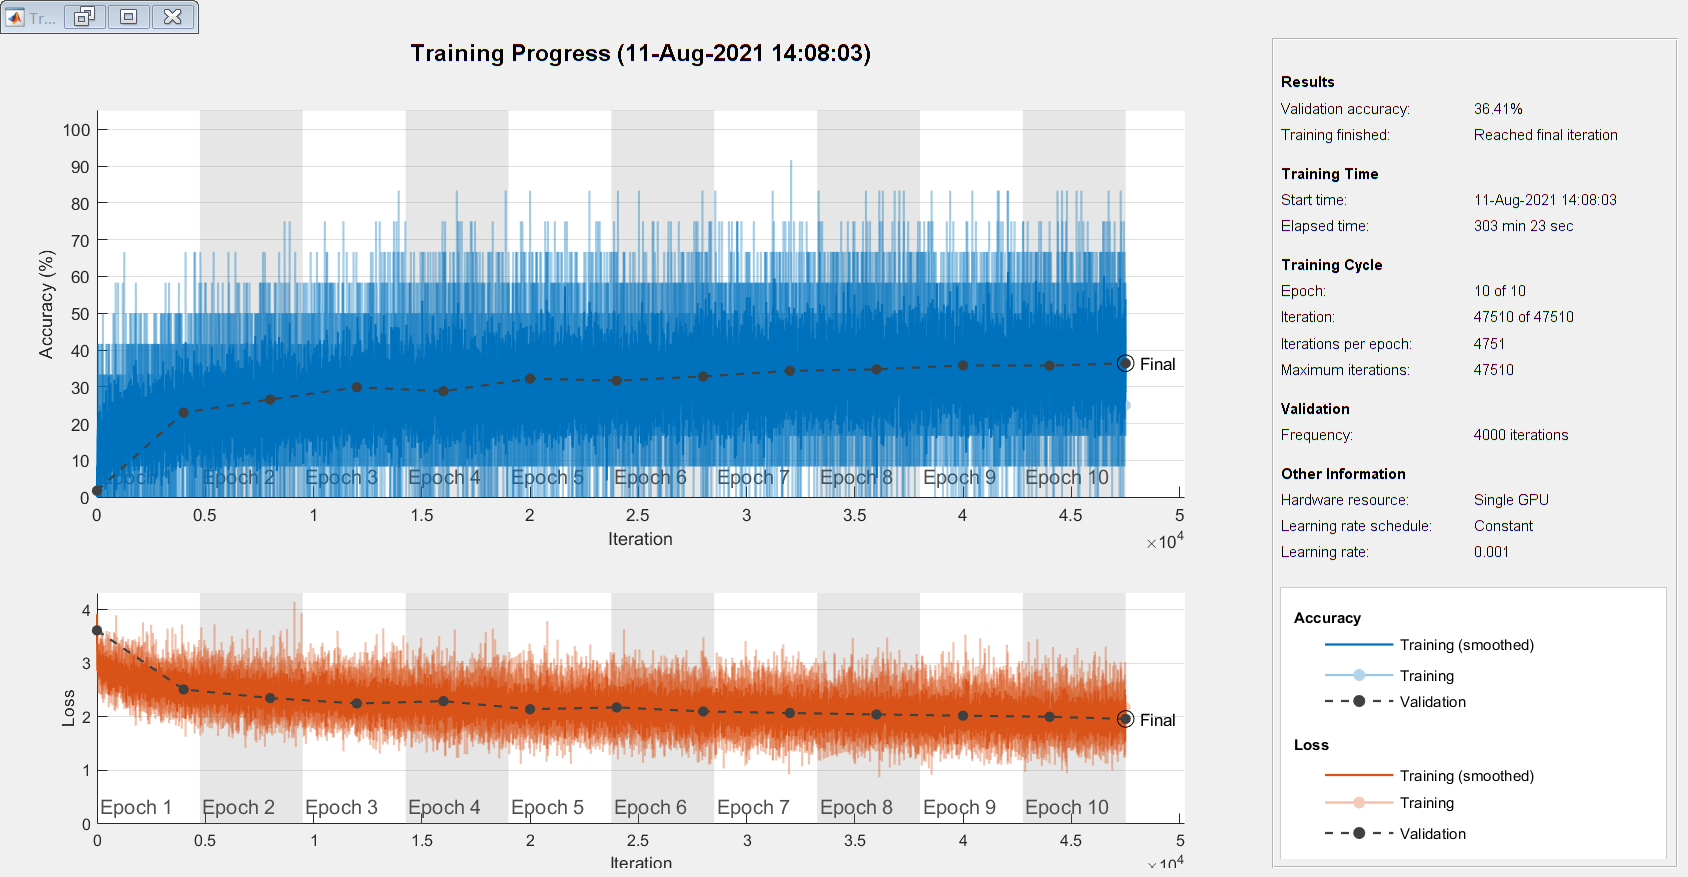

net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


traininfo = struct with fields:
               TrainingLoss: [1×47510 double]
           TrainingAccuracy: [1×47510 double]
             ValidationLoss: [1×47510 double]
         ValidationAccuracy: [1×47510 double]
              BaseLearnRate: [1×47510 double]
        FinalValidationLoss: 1.9607
    FinalValidationAccuracy: 36.4072


[net, traininfo] = trainNetwork(resized_art_Train, lgraph, options)